% code for plot results of Widefield imaging, which contain functions listed
% below
% Align neural activity of different trails by behavior events
% plot aligned neural activity of each trial (line + heatmap)
% plot activity correlation of each brain region
% plot neural activity sequence averaged by specific timebin
% plot neural activity averaged by specific behavior
% cut and align the neural activity based on task event written by NY
clear all;
close all;
clc;

% cut and align the neural activity based on task event written by NY
Animal = {'tph209','tph218','tph228'}; %{'tph189','tph199','tph209','tph218','tph228'};
Date = {'20230828','20230828','20230828'};%{'20230423','20230602','20230819','20230819','20230819'}; %{'20230421','20230530','20230817','20230817','20230817'};
totalTrial = 150;
Key = {'roving10s','roving10s','roving10s'};%{'heavy90','heavy90','heavy90h','heavy90h','heavy90h'}; %{'light90','light90','light90h','light90h','light90h'};
cellset_num = {5,5,5};%{5,5,1,2,2}; %{3,3,0,0,0}; % num of session in all sessions % start from 0behavior_neural_time
categorize = 'depth'; %'depth'; % categorize neurons by 'layer' or 'depth'
layer_bounds_um = {[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[131,203,344,344,345,376],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[168,373,418,437,451],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[126,40,173,206],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219],[20,102,143,316,219]}%[left, center,right] of the

layer_bounds_um = 1×23 の cell 配列
    {[131 203 344 344 345 376]}    {[131 203 344 344 345 376]}    {[131 203 344 344 345 376]}    {[131 203 344 344 345 376]}    {[131 203 344 344 345 376]}    {[168 373 418 437 451]}    {[168 373 418 437 451]}    {[168 373 418 437 451]}    {[168 373 418 437 451]}    {[168 373 418 437 451]}    {[168 373 418 437 451]}    {[126 40 173 206]}    {[126 40 173 206]}    {[126 40 173 206]}    {[126 40 173 206]}    {[126 40 173 206]}    {[126 40 173 206]}    {[20 102 143 316 219]}    {[20 102 143 316 219]}    {[20 102 143 316 219]}    {[20 102 143 316 219]}    {[20 102 143 316 219]}    {[20 102 143 316 219]}


%     Inscopix imaging FOV 
Kota_alignment = 0; %0: do not use, 1:use
% Define the folder where the CSV files are located
pullAlignFolderPath = '/home/naohiro/Documents/Inscopix_Projects/tph312_314_316_317_thres25/output';
% need to be fixed because reverse pattern is different between tph189 and tph199
image_reverse = {1,0,0};%{0,0,1,0,0}; %0: tph199 type orientation, 1: arc247 type orientation
% gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022/';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation/202308'  filesep Date '_' Animal '_' Key]; % Linux
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% behavior_data = behavior_neural_time_convolved_zscored;
output_dir = ['/home/naohiro/Desktop/Doya_rotation/analysis/output/240718/']; %['/home/naohiro/Desktop/Doya_rotation/analysis/output/230913/imaging_multi/'];

% plot event triggered neural activity
force_thr = 50; 
position_thr = 10;
fps = 10;
before_event = 2; %1;
after_event  = 4; %2;
norm = 5; %0:no normalization or 1:normalization or 2:z scored or 3:z scored and take only significantly changed cell 
% 4:z scored by compared trials 5: z scored and align with trian data
% (half) and plot with test data (half) 6: z scored by before pull neural
% activity
% ランダムシードを設定
rng(1);

data_folders = cell(1,length(Animal));
% data_folders = [];
acc_neural_activity_data = cell(1,length(Animal));
acc_neural_property_data = cell(1,length(Animal));
% correspondences_table = cell(length(Animal));
for i = 1:length(Animal)
    % if i <=2 %temporal operation
    %    data_folders(i) = {['/media/naohiro/ADATA HV620S/Doya_rotation' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    % else
        data_folders(i) = {['/media/naohiro/ADATA HV620S/Doya_rotation/202308' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    % end
    % data_folders(i) = {['/media/naohiro/Volume/Nao_behavior/202403' filesep strjoin(Date(i)) '_' strjoin(Animal(i)) '_' strjoin(Key(i))]};
    load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);    
    neural_activity_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces.csv'],'NumHeaderLines',0);
    neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
    neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces-props.csv']);
    neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
    if contains(Key,'roving')
        all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
        correspondences_table = readtable([strjoin(data_folders(i)) filesep 'correspondences_table_roving_0.5.csv']);
    elseif contains(Key,'switching')
        all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_switching-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
        correspondences_table = readtable([strjoin(data_folder(i)) filesep 'correspondences_table_switching_0.5.csv']);         
    else
        all_neural_property_table = readtable([strjoin(data_folders(i)) filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
        correspondences_table = readtable([strjoin(data_folders(i)) filesep 'correspondences_table_ordinary_0.5.csv']);
    end
    cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==int32(cell2mat(cellset_num(i))),:);
    %%% have to return the line below %%%
    global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
    % global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
    local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
    acc_neural_activity_data{i} = neural_activity_data(:,local_acc_idx+1);
    acc_neural_property_data{i} = neural_property_data(local_acc_idx+1,:);
    %     load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(i)) '.mat']);
    %     data(i,:) = behavior_sequence_fps;
    % save table as mat file %%%have to change!variable names are different
    % save([strjoin(data_folders(i)) filesep Animal(i) '_neural_activity_' Date(i) '_' Key(i) '.mat'], 'acc_neural_activity_data', 'acc_neural_property_data');    
end

% % neural_activity_table = readtable(['D:\Doya_rotation' filesep Date '_' Animal '_' Key filesep 'cell traces.csv']);%,'NumHeaderLines',1);
% % neural_activity_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces.csv'],'NumHeaderLines',0);
% neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
% neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
% % neural_property_table = readtable(['/home/naohiro/Desktop/Doya_rotation/analysis/imaging_data/20230327_test' filesep 'cell_traces-props.csv']);
% neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
% neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
% if contains(Key,'roving')
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
% else
%     all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
%     correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
% end
% % all_neural_property_table = readtable([data_folder filesep 'all_cell_traces-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
% % correspondences_table = readtable([data_folder filesep 'correspondences_table_0.5.csv']); %correspondences_table_ordinary_0.5
% cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
% %%% have to return the line below %%%
% global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
% % global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'undecided'));
% local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
% acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
% acc_neural_property_data = neural_property_data(local_acc_idx+1,:);
% % acc_neural_activity_data = neural_activity_data(:,strcmp(table2array(neural_property_table(:,'Status')),'accepted'));
% % acc_neural_property_data = neural_property_data(strcmp(table2array(neural_property_table(:,'Status')),'accepted'),:);

sum(strcmp(table2array(neural_property_table(:,'Status')),'accepted'))

ans = 0

strcmp(neural_property_table(:,'Status'),'accepted')

ans = logical
   0


acc_neural_activity_data{1}

ans =    25.2240   -3.8027    1.9279   11.4500   18.3072   -1.3805    4.1796    9.5795   24.3012    3.8625   -3.6518   55.0633    3.9255    4.2003   20.1012   10.2303    1.9521    1.9238   33.6008    3.3186    2.7212    6.9700    4.9020   -1.3821   34.5820    6.2257   -7.3771   33.2550   -0.1592    1.1547   -1.0922    4.6453   16.0583   -2.0049   11.9585    4.1198   -1.2956   12.6770    7.3276    7.5843   -6.8790    1.4233   -0.7433   -5.7777    5.2990    2.9068    0.6362    2.8493   10.8721   38.8591
   23.3055   -1.0492    0.0230   11.2835   18.9409   -3.2420    3.1696   10.5531   23.8024    1.1513   -3.4070   55.7565    3.1299    1.4120   17.8018   11.0021   -0.2518    5.6309   33.1657    1.1771    2.1087    9.7158    6.3899   -2.5822   34.4247    5.9586   -4.5144   35.1370    0.2310    0.4629   -2.3958    6.0623   16.6455   -2.9188   11.0719    3.8559   -3.8483   11.2679    6.1176    6.7041   -7.3783    1.9932   -1.5084   -4.4966    5.8235    2.5380    2.3133    2.0468   11.2724   

acc_neural_property_data{1}

ans =   255.0000  255.0000  255.0000  116.0000   19.0000    1.0000    7.6158    1.0000
  255.0000  255.0000  255.0000  106.0000   52.0000    1.0000    6.7082    1.0000
  255.0000  255.0000  255.0000  114.0000   48.0000    1.0000    7.2801    1.0000
  255.0000  255.0000  255.0000  124.0000   51.0000    1.0000    6.7082    1.0000
  255.0000  255.0000  255.0000  118.0000   54.0000    1.0000    7.2801    1.0000
  255.0000  255.0000  255.0000   96.0000   28.0000    1.0000    8.2462    1.0000
  255.0000  255.0000  255.0000  127.0000   44.0000    1.0000    8.0623    1.0000
  255.0000  255.0000  255.0000  111.0000   68.0000    1.0000    7.2801    1.0000
  255.0000  255.0000  255.0000  105.0000   42.0000    1.0000    7.2111    1.0000
  255.0000  255.0000  255.0000  101.0000   61.0000    1.0000    8.0623    1.0000


if Kota_alignment == 1    
    % Get a list of all CSV files in the folder
    csvFiles = dir(fullfile(pullAlignFolderPath, '*.csv'));
    
    % Initialize an empty cell array to store the matrices
    AlinmentTimingCells = {};
    
    % Loop through each CSV file and read the data
    for k = 1:length(csvFiles)
        % Get the full file name and read the CSV file
        fileName = fullfile(pullAlignFolderPath, csvFiles(k).name);
        data = table2array(readtable(fileName));
        
        % Store the data in the cell array
        AlinmentTimingCells{k} = data;
    end
end

% % plot neural activity
% % addpath([working_directory 'PCA_and_ICA\Subaxis']);
% ylimit=[0 50];
% mean_acc_neural_activity = mean(acc_neural_activity_data,2);
% figure
% % for i = 1:size(acc_neural_activity_data,2)
% %     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
%     for j = 1:size(acc_neural_activity_data,2)
%         hold on 
%         r = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,acc_neural_activity_data(:,j));
%         hold off
%     end
%     alpha(r,0.1);
%     hold on
%     b = plot(0:0.1:(size(acc_neural_activity_data,1)-1)/10,mean_acc_neural_activity);
% %     title([brain_roi_name(i)], 'FontSize',6);
%     ylim(ylimit); 
%     ylabel('neural activity');
%     xlabel('time (sec)')
% 
% % end
% % saveas(gcf,[output_dir Animal '_' num2str(ylimit(2)) '_all_activity.png']);

uniqueDate = unique(Date);
uniqueAnimal = unique(Animal);
% % タイトルの長さをチェックし、条件に応じて変更
% max_title_length = 100; % タイトルの最大許容長さを設定
% if length(original_title) > max_title_length
%     new_title = 'default_activity_heatmap.png'; % タイトルが長すぎる場合の代替タイトル
% else
%     new_title = original_title; % タイトルが許容範囲内ならオリジナルのタイトルを使用
% end

% % plot neural activity heatmap
% addpath([working_directory 'Utility' filesep 'Subaxis']);
% climit = [0 50]
% figure
% set(gcf,'color','w');
% for i = 1:length(Animal) 
%     subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
%     clims = climit;
%     image = transpose(acc_neural_activity_data{i});
% %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
%     imagesc(0:0.1:(size(acc_neural_activity_data{i},1)-1)/10,1:size(acc_neural_activity_data{i},2),image,clims);
% %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
%     ylabel('cell');
%     xlabel('time (sec)');
% end
% 
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_' strrep(strjoin(uniqueAnimal),' ','_') '_all_activity_heatmap.png'];
% 
% saveas(gcf,filename);
% % close all;

% addpath([working_directory 'Utility' filesep 'Subaxis']);
% example_num = 5;
% display_start = 1; %113;
% ylimit=[0 150];
% figure
% for j = 1:length(Animal)
%     for i = 1:example_num
%         subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
%         b = plot(0:0.1:(size(acc_neural_activity_data{j},1)-1)/10,acc_neural_activity_data{j}(:,display_start+i));
%     %     title([brain_roi_name(i)], 'FontSize',6);
%         ylim(ylimit); 
%         xlim([0 (size(acc_neural_activity_data{j},1)-1)/10]);
%         xlabel('');
%         ylabel('');
% %         axis off;
%         box off;
%     %     ylabel('neural activity');
%     %     xlabel('time (sec)')
%     end
% end
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_exmple_activity_traces.png'];
% saveas(gcf,filename);

% 0:0.1:(size(acc_neural_activity_data,2)-1)/10

% % plot event triggered neural activity
% force_thr = 50;
% position_thr = 10;
% fps = 10;
% before_event = 2; %1;
% after_event  = 4; %2;
% norm = 2; %0:no normalization or 1:normalization or 2:z scored or 3:z scored and take only significantly changed cell
% 
% % for i = 1:length(Animal)
% %     load([strjoin(data_folders(i)) filesep strjoin(Animal(i)) '_behavior_' strjoin(Date(i)) '_' strjoin(Key(j)) '.mat']);
% % end

% j=1;
% load([strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
% var_list = who('-file' ,[strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
% % var_list = who -file /media/naohiro/ADATA HV620S/Doya_rotation/202308/20230819_tph228_heavy90h/tph228_behavior_20230819_heavy90h.mat
% disp(var_list);

% % plot example neural activity with behaviors
% addpath([working_directory 'Utility' filesep 'Subaxis']);
% example_num = 5;
% display_start = 1; %113;
% ylimit=[0 150];
% range_max =1000;
% figure
% for j = 1:length(Animal)
%     load([strjoin(data_folders(j)) filesep strjoin(Animal(j)) '_behavior_' strjoin(Date(j)) '_' strjoin(Key(j)) '.mat']);
%     for i = 1:example_num
%         subaxis(example_num+3,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
%         b = plot(0:0.1:(range_max-1)/10,acc_neural_activity_data{j}(1:range_max,display_start+i));
%     %     title([brain_roi_name(i)], 'FontSize',6);
%         ylim(ylimit); 
%         xlim([0 (range_max-1)/10]);
%         xlabel('');
%         ylabel('');
% %         axis off;
%         box off;
%         %     ylabel('neural activity');
%     %     xlabel('time (sec)')
%     end
% 
%     for i = 1:3
%         subaxis(example_num+3,length(Animal),2*(i+example_num)+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%         normalized_behavior = normalize_rows(transpose(behavior_neural_time(1:range_max,5+i)));
%         b = plot(0:0.1:(range_max-1)/10,normalized_behavior);
%     %     title([brain_roi_name(i)], 'FontSize',6);
%         ylim([-0.2 1.2]); 
%         xlim([0 (range_max-1)/10]);
%         xlabel('');
%         ylabel('');
% %         axis off;
%         box off;
%     %     ylabel('neural activity');
%     %     xlabel('time (sec)')
%     end
% end
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_exmple_activity_behavior_traces.png'];
% saveas(gcf,filename);

% Calc cell depth from pixel value
% image_reverse = 0; %0: tph199 type orientation, 1: arc247 type orientation
depth = cell(1,length(Animal));
if strcmp(categorize, 'depth') == 1
    for i = 1:length(Animal)        
        if image_reverse{i} == 0
            depth{i} = 1050 - acc_neural_property_data{i}(:,4)*1050/(1280/4);    %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
        elseif image_reverse{i} == 2
            depth = 1050 - acc_neural_property_data{i}(:,4)*1050/(1280/4); 
        else
            depth{i} = acc_neural_property_data{i}(:,4)*1050/(1280/4);
    %     depth = 1100 - acc_neural_property_data(:,4)*1000/(1066/4);   %arc247: acc_neural_property_data(:,4)*1000/(1066/4); %tph189,tph199: 1100 - acc_neural_property_data(:,4)*1000/(1066/4); 
        end
    end
    depth_conc = depth{1};
    for i_animal = 2:length(Animal)
        depth_conc = vertcat(depth_conc, depth{i_animal});
    end
end

% determine which layer each cell belong by cell position
if strcmp(categorize, 'layer') == 1
    pointAreas = cell(1,length(Animal));
    for i = 1:length(Animal)
    %     layer_bounds_um = [140;250;260]; %[left, center,right] of the
    %     Inscopix imaging FOV
        layer_bounds_pix = layer_bounds_um{i} * (1280/4) /1050; 
        layer_bounds_len = length(layer_bounds_pix);
        x_pix = linspace(1, 200, layer_bounds_len);
        % y axis:acc_neural_property_data(:,4), x axis:acc_neural_property_data(:,5)
        % TODO: have to be reverse y axis and x axis depending on the orientation of
        % the image
        if image_reverse{i} == 0
            neural_locations = [acc_neural_property_data{i}(:,5), acc_neural_property_data{i}(:,4)];
        elseif image_reverse{i} == 2
            neural_locations = [800/4 - acc_neural_property_data{i}(:,5), 1280/4 - acc_neural_property_data{i}(:,4)];        
        else
            % reverse layer_bounds_pix
            layer_bounds_pix = flip(layer_bounds_pix)
            neural_locations = [1280/4 - acc_neural_property_data{i}(:,5), acc_neural_property_data{i}(:,4)];       
        end
        %reshape neural_locations to N*2
        % combine x_pix and layer_bounds_pix to 3*2
        linePoints = [x_pix(:), layer_bounds_pix(:)];
        % determine the layer each cell belong based on the matlab function
        % 0: layer2/3, 1: layer5
        pointAreas{i} = classifyPoints(neural_locations, linePoints);
        % save table as mat file %%%have to change!variable names are different
        % save([strjoin(data_folders(i)) filesep Animal(i) '_neural_activity_' Date(i) '_' Key(i) '.mat'], 'pointAreas', '-append');     
    end
    pointAreas_conc = pointAreas{1};
    for i_animal = 2:length(Animal)
        pointAreas_conc = vertcat(pointAreas_conc, pointAreas{i_animal});
    end 
end

trial_start_act_multi_animals = cell(1,length(Animal));
trial_end_act_multi_animals   = cell(1,length(Animal));
position_act_multi_animals    = cell(1,length(Animal));
force_act_multi_animals       = cell(1,length(Animal));
reward_act_multi_animals      = cell(1,length(Animal));
trial_start_act_raw_multi_animals = cell(1,length(Animal));
trial_end_act_raw_multi_animals   = cell(1,length(Animal));
position_act_raw_multi_animals    = cell(1,length(Animal));
force_act_raw_multi_animals       = cell(1,length(Animal));
reward_act_raw_multi_animals      = cell(1,length(Animal));
start_I    = cell(1,length(Animal));
end_I      = cell(1,length(Animal));
position_I = cell(1,length(Animal));
force_I    = cell(1,length(Animal));
reward_I   = cell(1,length(Animal));
trial_start_act_max_act_times = cell(1,length(Animal));
trial_end_act_max_act_times   = cell(1,length(Animal));
position_act_max_act_times    = cell(1,length(Animal));
force_act_max_act_times       = cell(1,length(Animal));
reward_act_max_act_times      = cell(1,length(Animal));
% indices1s = cell(1,length(Animal));
% indices2s = cell(1,length(Animal));
for i_animal = 1:length(Animal)
    load([strjoin(data_folders(i_animal)) filesep strjoin(Animal(i_animal)) '_behavior_' strjoin(Date(i_animal)) '_' strjoin(Key(i_animal)) '.mat']);
    % 'behavior_neural_time'
    trial_start = behavior_neural_time(:,3);
    trial_end   = behavior_neural_time(:,4);
    position    = behavior_neural_time(:,6);
    force       = behavior_neural_time(:,7);
    reward      = behavior_neural_time(:,8);
    % find index of each event
    trial_start_idx = find(trial_start == 1);
    trial_end_idx   = find(trial_end == 1);
    force_idx       = find(force > force_thr);
    reward_idx      = find(reward == 1); 
    position_diff   = diff(position);
    position_idx    = find(position_diff > position_thr);
    % idxs = [trial_start_idx, trial_end, force_idx, reward_idx];
    % event_acts = []; % trial_start_act, trial_end_act, force_act, reward_act
    trial_start_act = zeros(size(acc_neural_activity_data{i_animal},2),fps*(before_event+after_event)+1);
    trial_end_act   = zeros(size(acc_neural_activity_data{i_animal},2),fps*(before_event+after_event)+1);
    position_act    = zeros(size(acc_neural_activity_data{i_animal},2),fps*(before_event+after_event)+1);
    force_act       = zeros(size(acc_neural_activity_data{i_animal},2),fps*(before_event+after_event)+1);
    reward_act      = zeros(size(acc_neural_activity_data{i_animal},2),fps*(before_event+after_event)+1);
    sig_cell_idxs   = cell(0,5);
    
    % only count first idx in 1 second
    temp_position_idx = position_idx(1);
    for i = 2:length(position_idx)
        if position_idx(i) - temp_position_idx(end) >= fps
            temp_position_idx(end+1) = position_idx(i);
        end
    end
    position_idx = temp_position_idx;
    
    temp_force_idx = force_idx(1);
    for i = 2:length(force_idx)
        if force_idx(i) - temp_force_idx(end) >= fps
            temp_force_idx(end+1) = force_idx(i);
        end
    end
    force_idx = temp_force_idx;
    
    temp_reward_idx = reward_idx(1);
    for i = 2:length(reward_idx)
        if reward_idx(i) - temp_reward_idx(end) >= fps
            temp_reward_idx(end+1) = reward_idx(i);
        end
    end
    reward_idx = temp_reward_idx;
    
    % for i = 1:size(idxs,2)
    %     temp_event_acts = zeros(size(acc_neural_activity_data,1),fps*(before_event+after_event));
    exception_count = 0;
    trial_start_acts = {};
    for j = 1:length(trial_start_idx)
        if trial_start_idx(j)-fps*before_event<=0 | trial_start_idx(j)+fps*after_event>size(acc_neural_activity_data{i_animal},1)
            exception_count = exception_count + 1;
        else
            trial_start_act = trial_start_act+transpose(acc_neural_activity_data{i_animal}(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:)); 
            trial_start_acts{end+1}= transpose(acc_neural_activity_data{i_animal}(trial_start_idx(j)-fps*before_event:trial_start_idx(j)+fps*after_event,:));
        end
    end
    trial_start_act = trial_start_act/(length(trial_start_idx)-exception_count);
    trial_start_acts = reshape(cell2mat(trial_start_acts),[size(acc_neural_activity_data{i_animal}, 2) size(trial_start_act,2) length(trial_start_idx)-exception_count]); %[191 31 147]);
    if norm == 1
        trial_start_act = normalize_rows(trial_start_act);
    elseif norm ==2 || norm ==4
           trial_start_act = zscore_rows(trial_start_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data{i_animal}, 2)
            [~,max_idx] = max(mean(trial_start_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_trial_start_acts = trial_start_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(trial_start_acts(i_cell,:)),squeeze(max_trial_start_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{1} = sig_cell_idx;
        end
        trial_start_act = zscore_rows(trial_start_act(find(sig_cell_idx==1),:));
    end
    trial_start_act_raw = trial_start_act;
    [M,start_I{i_animal}] = max(trial_start_act,[],2);
    trial_start_act = cat(2,start_I{i_animal},trial_start_act);
    trial_start_act = sortrows(trial_start_act);
    trial_start_act_max_act_times{i_animal} = trial_start_act(:,1)/10 -2;
    trial_start_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(trial_start_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);
        % indices1s{i_animal} = indices1; indices2s{i_animal} = indices2
        % データを分離する配列を作成
        % train_test_indice = ones(1, L); train_test_indice(indices2) = 2;
        % if i_animal == 1
        %     train_test_indices = train_test_indice;       
        % else
        %     train_test_indices = vertcat(train_test_indices, train_test_indice);
        % end         
        % 2つのテンソルに分割
        trial_start_acts_train = trial_start_acts(:, :, indices1);
        trial_start_acts_test  = trial_start_acts(:, :, indices2);
        % sort with train data
        trial_start_act_train_raw = mean(trial_start_acts_train,3);
        trial_start_act_test_raw  = mean(trial_start_acts_test,3);
        trial_len = size(trial_start_act_train_raw,2);
        [M,start_I{i_animal}] = max(trial_start_act_train_raw,[],2);
        trial_start_act = cat(2,start_I{i_animal},trial_start_act_train_raw, trial_start_act_test_raw);
        trial_start_act = sortrows(trial_start_act);
        trial_start_act_max_act_times{i_animal} = trial_start_act(:,1)/10 -2;
        trial_start_act(:,1) = [];
        trial_start_act_train = trial_start_act(:,1:trial_len);
        trial_start_act_test  = trial_start_act(:,trial_len+1:size(trial_start_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        trial_start_act = zscore_rows(trial_start_act_test);
    end

    exception_count = 0;
    trial_end_acts = {};
    for j = 1:length(trial_end_idx)
        if trial_end_idx(j)-fps*before_event<=0 | trial_end_idx(j)+fps*after_event>size(acc_neural_activity_data{i_animal},1)
            exception_count = exception_count + 1;
        else
            trial_end_act = trial_end_act+transpose(acc_neural_activity_data{i_animal}(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:)); 
            trial_end_acts{end+1}= transpose(acc_neural_activity_data{i_animal}(trial_end_idx(j)-fps*before_event:trial_end_idx(j)+fps*after_event,:));
        end
    end
    trial_end_act = trial_end_act/(length(trial_end_idx)-exception_count);
    trial_end_acts = reshape(cell2mat(trial_end_acts),[size(acc_neural_activity_data{i_animal}, 2) size(trial_end_act,2) length(trial_end_idx)-exception_count]);
    if norm == 1
        trial_end_act = normalize_rows(trial_end_act);
    elseif norm ==2
       trial_end_act = zscore_rows(trial_end_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data{i_animal}, 2)
            [~,max_idx] = max(mean(trial_end_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_trial_end_acts = trial_end_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(trial_end_acts(i_cell,:)),squeeze(max_trial_end_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{2} = sig_cell_idx;
        end
        trial_end_act = zscore_rows(trial_end_act(find(sig_cell_idx==1),:));
    end
    trial_end_act_raw = trial_end_act;
    [M,end_I{i_animal}] = max(trial_end_act,[],2);
    trial_end_act = cat(2,end_I{i_animal},trial_end_act);
    trial_end_act = sortrows(trial_end_act);
    trial_end_act_max_act_times{i_animal} = trial_end_act(:,1)/10 -2;
    trial_end_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(trial_end_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);        
        % 2つのテンソルに分割
        trial_end_acts_train = trial_end_acts(:, :, indices1);
        trial_end_acts_test  = trial_end_acts(:, :, indices2);
        % sort with train data
        trial_end_act_train_raw = mean(trial_end_acts_train,3);
        trial_end_act_test_raw  = mean(trial_end_acts_test,3);
        trial_len = size(trial_end_act_train_raw,2);
        [M,end_I{i_animal}] = max(trial_end_act_train_raw,[],2);
        trial_end_act = cat(2,end_I{i_animal},trial_end_act_train_raw, trial_end_act_test_raw);
        trial_end_act = sortrows(trial_end_act);
        trial_end_act_max_act_times{i_animal} = trial_end_act(:,1)/10 -2;
        trial_end_act(:,1) = [];
        trial_end_act_train = trial_end_act(:,1:trial_len);
        trial_end_act_test  = trial_end_act(:,trial_len+1:size(trial_end_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        trial_end_act = zscore_rows(trial_end_act_test);
    end

    exception_count = 0;
    position_acts = {};
    for j = 1:length(position_idx)
        if position_idx(j)-fps*before_event<=0 | position_idx(j)+fps*after_event>size(acc_neural_activity_data{i_animal},1)
            exception_count = exception_count + 1;
        else
            position_act = position_act+transpose(acc_neural_activity_data{i_animal}(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:)); 
            position_acts{end+1}= transpose(acc_neural_activity_data{i_animal}(position_idx(j)-fps*before_event:position_idx(j)+fps*after_event,:));
        end
    end
    position_act = position_act/(length(force_idx)-exception_count);
    position_acts = reshape(cell2mat(position_acts),[size(acc_neural_activity_data{i_animal}, 2) size(position_act,2) length(position_idx)-exception_count]);
    if norm == 1
        position_act = normalize_rows(position_act);
    elseif norm ==2
           position_act = zscore_rows(position_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data{i_animal}, 2)
            [~,max_idx] = max(mean(position_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_position_acts = position_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(position_acts(i_cell,:)),squeeze(max_position_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{3} = sig_cell_idx;
        end
        position_act = zscore_rows(position_act(find(sig_cell_idx==1),:));
    end
    position_act_raw = position_act;
    [M,pos_I{i_animal}] = max(position_act,[],2);
    position_act = cat(2,pos_I{i_animal},position_act);
    position_act = sortrows(position_act);
    position_act_max_act_times{i_animal} = position_act(:,1)/10 -2;
    position_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(position_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);        
        % 2つのテンソルに分割
        position_acts_train = position_acts(:, :, indices1);
        position_acts_test  = position_acts(:, :, indices2);
        % sort with train data
        position_act_train_raw = mean(position_acts_train,3);
        position_act_test_raw  = mean(position_acts_test,3);
        trial_len = size(position_act_train_raw,2);
        [M,position_I{i_animal}] = max(position_act_train_raw,[],2);
        position_act = cat(2,position_I{i_animal},position_act_train_raw, position_act_test_raw);
        position_act = sortrows(position_act);
        position_act_max_act_times{i_animal} = position_act(:,1)/10 -2;
        position_act(:,1) = [];
        position_act_train = position_act(:,1:trial_len);
        position_act_test  = position_act(:,trial_len+1:size(position_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        position_act = zscore_rows(position_act_test);
    end    
    
    exception_count = 0;
    force_acts = {};
    for j = 1:length(force_idx)
        if force_idx(j)-fps*before_event<=0 | force_idx(j)+fps*after_event>size(acc_neural_activity_data{i_animal},1)
            exception_count = exception_count + 1;
        else
            force_act = force_act+transpose(acc_neural_activity_data{i_animal}(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:)); 
            force_acts{end+1}= transpose(acc_neural_activity_data{i_animal}(force_idx(j)-fps*before_event:force_idx(j)+fps*after_event,:));
        end
    end
    force_act = force_act/(length(force_idx)-exception_count);
    force_acts = reshape(cell2mat(force_acts),[size(acc_neural_activity_data{i_animal}, 2) size(force_act,2) length(force_idx)-exception_count]); %-1]);
    if norm == 1
        force_act = normalize_rows(force_act);
    elseif norm ==2
           force_act = zscore_rows(force_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data{i_animal}, 2)
            [~,max_idx] = max(mean(force_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_force_acts = force_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(force_acts(i_cell,:)),squeeze(max_force_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{4} = sig_cell_idx;
        end
        force_act = zscore_rows(force_act(find(sig_cell_idx==1),:));
    end
    force_act_raw = force_act;
    [M,force_I{i_animal}] = max(force_act,[],2);
    force_act = cat(2,force_I{i_animal},force_act);
    force_act = sortrows(force_act);
    force_act_max_act_times{i_animal} = force_act(:,1)/10 -2;
    force_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(force_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);         
        % 2つのテンソルに分割
        force_acts_train = force_acts(:, :, indices1);
        force_acts_test  = force_acts(:, :, indices2);
        % sort with train data
        force_act_train_raw = mean(force_acts_train,3);
        force_act_test_raw  = mean(force_acts_test,3);
        trial_len = size(force_act_train_raw,2);
        [M,force_I{i_animal}] = max(force_act_train_raw,[],2);
        force_act = cat(2,force_I{i_animal},force_act_train_raw, force_act_test_raw);
        force_act = sortrows(force_act);
        force_act_max_act_times{i_animal} = force_act(:,1)/10 -2;
        force_act(:,1) = [];
        force_act_train = force_act(:,1:trial_len);
        force_act_test  = force_act(:,trial_len+1:size(force_act,2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        force_act = zscore_rows(force_act_test);
    end    

    exception_count = 0;
    reward_acts = {};
    for j = 1:length(reward_idx)
        if reward_idx(j)-fps*before_event<=0 | reward_idx(j)+fps*after_event>size(acc_neural_activity_data{i_animal},1)
            exception_count = exception_count + 1;
        else
            reward_act = reward_act+transpose(acc_neural_activity_data{i_animal}(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:)); 
            reward_acts{end+1}= transpose(acc_neural_activity_data{i_animal}(reward_idx(j)-fps*before_event:reward_idx(j)+fps*after_event,:));
        end
    end
    reward_act = reward_act/(length(reward_idx)-exception_count);
    reward_acts = reshape(cell2mat(reward_acts),[size(acc_neural_activity_data{i_animal}, 2) size(reward_act,2) length(reward_idx)-exception_count]);
    if norm == 1
        reward_act = normalize_rows(reward_act);
    elseif norm ==2
       reward_act = zscore_rows(reward_act); 
    elseif norm ==3
        sig_cell_idx = zeros(1,size(acc_neural_activity_data{i_animal}, 2));
        for i_cell = 1:size(acc_neural_activity_data{i_animal}, 2)
            [~,max_idx] = max(mean(reward_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_reward_acts = reward_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(reward_acts(i_cell,:)),squeeze(max_reward_acts),'Vartype','unequal');
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs{5} = sig_cell_idx;
        end
        reward_act = zscore_rows(reward_act(find(sig_cell_idx==1),:));
        % save table as mat file
        % save([strjoin(data_folders(i_animal)) filesep strjoin(Animal(i_animal)) '_neural_activity_' strjoin(Date(i_animal)) '_' strjoin(Key(i_animal)) '.mat'], 'sig_cell_idxs', '-append');  
    end
    reward_act_raw = reward_act;
    [M,reward_I{i_animal}] = max(reward_act,[],2);
    reward_act = cat(2,reward_I{i_animal},reward_act);
    reward_act = sortrows(reward_act);
    reward_act_max_act_times{i_animal} = reward_act(:,1)/10 -2;
    reward_act(:,1) = [];
    if norm == 5
        % separete train and test of trial_start_acts
        L = size(reward_acts, 3);
        % 最後の次元に基づいてランダムにインデックスをシャッフル
        indices = randperm(L);        
        % インデックスを2つのグループに分ける
        half_L1 = ceil(L / 2); % (L+1)/2のサイズ
        half_L2 = floor(L / 2); % (L-1)/2のサイズ        
        indices1 = indices(1:half_L1);
        indices2 = indices(half_L1+1:end);         
        % 2つのテンソルに分割
        reward_acts_train = reward_acts(:, :, indices1);
        reward_acts_test  = reward_acts(:, :, indices2);
        % sort with train data
        reward_act_train_raw = mean(reward_acts_train, 3);
        reward_act_test_raw  = mean(reward_acts_test, 3);
        trial_len = size(reward_act_train_raw, 2);
        [M, reward_I{i_animal}] = max(reward_act_train_raw, [], 2);
        reward_act = cat(2, reward_I{i_animal}, reward_act_train_raw, reward_act_test_raw);
        reward_act = sortrows(reward_act);
        reward_act_max_act_times{i_animal} = reward_act(:, 1) / 10 - 2;
        reward_act(:, 1) = [];
        reward_act_train = reward_act(:, 1:trial_len);
        reward_act_test  = reward_act(:, trial_len+1:size(reward_act, 2));
        % zscore and return only test data
        % trial_start_act_raw = trial_start_act_test_raw;
        reward_act = zscore_rows(reward_act_test);
    end    

    trial_start_act_multi_animals{i_animal} = trial_start_act;
    trial_end_act_multi_animals{i_animal}   = trial_end_act;
    position_act_multi_animals{i_animal}    = position_act;
    force_act_multi_animals{i_animal}       = force_act;
    reward_act_multi_animals{i_animal}      = reward_act;
    trial_start_act_raw_multi_animals{i_animal} = trial_start_act_raw;
    trial_end_act_raw_multi_animals{i_animal}   = trial_end_act_raw;
    position_act_raw_multi_animals{i_animal}    = position_act_raw;
    force_act_raw_multi_animals{i_animal}       = force_act_raw;
    reward_act_raw_multi_animals{i_animal}      = reward_act_raw;

    if norm == 5
        trial_start_act_train_raw_multi_animals{i_animal} = trial_start_act_train_raw;
        trial_end_act_train_raw_multi_animals{i_animal}   = trial_end_act_train_raw;
        position_act_train_raw_multi_animals{i_animal}    = position_act_train_raw;
        force_act_train_raw_multi_animals{i_animal}       = force_act_train_raw;
        reward_act_train_raw_multi_animals{i_animal}      = reward_act_train_raw;   
        trial_start_act_test_raw_multi_animals{i_animal}  = zscore_rows(trial_start_act_test_raw);
        trial_end_act_test_raw_multi_animals{i_animal}    = zscore_rows(trial_end_act_test_raw);
        position_act_test_raw_multi_animals{i_animal}     = zscore_rows(position_act_test_raw);
        force_act_test_raw_multi_animals{i_animal}        = zscore_rows(force_act_test_raw);
        reward_act_test_raw_multi_animals{i_animal}       = zscore_rows(reward_act_test_raw);           
    end

%     if i_animal == 1
%         trial_start_act_multi_animals = trial_start_act;
%         trial_end_act_multi_animals   = trial_end_act;
%         position_act_multi_animals    = positon_act;
%         force_act_multi_animals       = force_act;
%         reward_act_multi_animals      = reward_act;
%     else
%         trial_start_act_multi_animals = [trial_start_act_multi_animals; trial_start_act];
%         trial_end_act_multi_animals   = [trial_end_act_multi_animals; trial_end_act];
%         position_act_multi_animals    = [position_act_multi_animals; positon_act];
%         force_act_multi_animals       = [force_act_multi_animals; force_act];
%         reward_act_multi_animals      = [reward_act_multi_animals; reward_act];        
%     end
end

trial_start_act_conc = trial_start_act_raw_multi_animals{1};
trial_end_act_conc   = trial_end_act_raw_multi_animals{1};
position_act_conc    = position_act_raw_multi_animals{1};
force_act_conc       = force_act_raw_multi_animals{1};
reward_act_conc      = reward_act_raw_multi_animals{1};
trial_start_act_max_act_times_conc = trial_start_act_max_act_times{1};
trial_end_act_max_act_times_conc   = trial_end_act_max_act_times{1};
position_act_max_act_times_conc    = position_act_max_act_times{1};
force_act_max_act_times_conc       = force_act_max_act_times{1};
reward_act_max_act_times_conc      = reward_act_max_act_times{1};
for i_animal = 2:length(Animal)
    trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_raw_multi_animals{i_animal});
    trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_raw_multi_animals{i_animal});
    position_act_conc = vertcat(position_act_conc, position_act_raw_multi_animals{i_animal});
    force_act_conc = vertcat(force_act_conc, force_act_raw_multi_animals{i_animal});
    reward_act_conc = vertcat(reward_act_conc, reward_act_raw_multi_animals{i_animal});
    trial_start_act_max_act_times_conc = vertcat(trial_start_act_max_act_times_conc, trial_start_act_max_act_times{i_animal});
    trial_end_act_max_act_times_conc   = vertcat(trial_end_act_max_act_times_conc, trial_end_act_max_act_times{i_animal});
    position_act_max_act_times_conc    = vertcat(position_act_max_act_times_conc, position_act_max_act_times{i_animal});
    force_act_max_act_times_conc       = vertcat(force_act_max_act_times_conc, force_act_max_act_times{i_animal});
    reward_act_max_act_times_conc      = vertcat(reward_act_max_act_times_conc, reward_act_max_act_times{i_animal});
end

if norm == 5
    trial_start_act_train_conc = trial_start_act_train_raw_multi_animals{1};
    trial_end_act_train_conc   = trial_end_act_train_raw_multi_animals{1};
    position_act_train_conc    = position_act_train_raw_multi_animals{1};
    force_act_train_conc       = force_act_train_raw_multi_animals{1};
    reward_act_train_conc      = reward_act_train_raw_multi_animals{1};
    trial_start_act_test_conc  = trial_start_act_test_raw_multi_animals{1};
    trial_end_act_test_conc    = trial_end_act_test_raw_multi_animals{1};
    position_act_test_conc     = position_act_test_raw_multi_animals{1};
    force_act_test_conc        = force_act_test_raw_multi_animals{1};
    reward_act_test_conc       = reward_act_test_raw_multi_animals{1};    
    for i_animal = 2:length(Animal)
        trial_start_act_train_conc = vertcat(trial_start_act_train_conc, trial_start_act_train_raw_multi_animals{i_animal});
        trial_end_act_train_conc   = vertcat(trial_end_act_train_conc, trial_end_act_train_raw_multi_animals{i_animal});
        position_act_train_conc    = vertcat(position_act_train_conc, position_act_train_raw_multi_animals{i_animal});
        force_act_train_conc       = vertcat(force_act_train_conc, force_act_train_raw_multi_animals{i_animal});
        reward_act_train_conc      = vertcat(reward_act_train_conc, reward_act_train_raw_multi_animals{i_animal});
        trial_start_act_test_conc  = vertcat(trial_start_act_test_conc, trial_start_act_test_raw_multi_animals{i_animal});
        trial_end_act_test_conc    = vertcat(trial_end_act_test_conc, trial_end_act_test_raw_multi_animals{i_animal});
        position_act_test_conc     = vertcat(position_act_test_conc, position_act_test_raw_multi_animals{i_animal});
        force_act_test_conc        = vertcat(force_act_test_conc, force_act_test_raw_multi_animals{i_animal});
        reward_act_test_conc       = vertcat(reward_act_test_conc, reward_act_test_raw_multi_animals{i_animal});        
    end
end
    % trial_start_act_train_raw = mean(trial_start_acts_train,3);
    % trial_start_act_test_raw
        % trial_start_act_conc = trial_start_act_multi_animals{1};
% trial_end_act_conc   = trial_end_act_multi_animals{1};
% position_act_conc    = position_act_multi_animals{1};
% force_act_conc       = force_act_multi_animals{1};
% reward_act_conc      = reward_act_multi_animals{1};
% trial_start_act_max_act_times_conc = trial_start_act_max_act_times{1};
% trial_end_act_max_act_times_conc   = trial_end_act_max_act_times{1};
% position_act_max_act_times_conc    = position_act_max_act_times{1};
% force_act_max_act_times_conc       = force_act_max_act_times{1};
% reward_act_max_act_times_conc      = reward_act_max_act_times{1};
% for i_animal = 2:length(Animal)
%     trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_multi_animals{i_animal});
%     trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_multi_animals{i_animal});
%     position_act_conc = vertcat(position_act_conc, position_act_multi_animals{i_animal});
%     force_act_conc = vertcat(force_act_conc, force_act_multi_animals{i_animal});
%     reward_act_conc = vertcat(reward_act_conc, reward_act_multi_animals{i_animal});
%     trial_start_act_max_act_times_conc = vertcat(trial_start_act_max_act_times_conc, trial_start_act_max_act_times{i_animal});
%     trial_end_act_max_act_times_conc   = vertcat(trial_end_act_max_act_times_conc, trial_end_act_max_act_times{i_animal});
%     position_act_max_act_times_conc    = vertcat(position_act_max_act_times_conc, position_act_max_act_times{i_animal});
%     force_act_max_act_times_conc       = vertcat(force_act_max_act_times_conc, force_act_max_act_times{i_animal});
%     reward_act_max_act_times_conc      = vertcat(reward_act_max_act_times_conc, reward_act_max_act_times{i_animal});
% end

% caluculate ETA of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    pull_sig_cell_idxs   = cell(0,length(AlinmentTimingCells)+1);
    pull_actss = cell(0,length(AlinmentTimingCells)+1);
    % pull_Is = cell(0,length(AlinmentTimingCells)+1);
    pull_actss_train = cell(0,length(AlinmentTimingCells)+1);
    pull_act_store = cell(length(AlinmentTimingCells),length(Animal));
    for i = 1:length(AlinmentTimingCells)
        for k_animal = 1:length(Animal)
            pull_act      = zeros(size(acc_neural_activity_data{k_animal},2),fps*(before_event+after_event)+1);
            exception_count = 0;
            pull_acts = {};
            pull_idx = AlinmentTimingCells{i};
            for j = 1:size(pull_idx,2)
                if pull_idx(k_animal,j)-fps*before_event<=0 | pull_idx(k_animal,j)+fps*after_event>size(acc_neural_activity_data{k_animal},1)
                    exception_count = exception_count + 1;
                else
                    pull_act = pull_act+transpose(acc_neural_activity_data{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:)); 
                    pull_acts{end+1}= transpose(acc_neural_activity_data{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:));
                end
            end
            pull_act = pull_act/(size(pull_idx,2)-exception_count);
            pull_acts = reshape(cell2mat(pull_acts),[size(acc_neural_activity_data{k_animal}, 2) size(pull_act,2) size(pull_idx,2)-exception_count]);
            if norm == 1
                pull_act = normalize_rows(pull_act);
            elseif norm ==2
               pull_act = zscore_rows(pull_act); 
            elseif norm ==6
               pull_act = zscore_rows_by_before_pull(pull_act);               
            elseif norm == 4
               if i == 1 | i == 3 | i == 4
                   pull_act_store{i,k_animal} = pull_act;
                   pull_act = zscore_rows(pull_act); 
               elseif i == 2
                   pull_act = zscore_rows_by_diff_matrix(pull_act,pull_act_store{1,k_animal});
               elseif i == 5 | i == 6
                   pull_act = zscore_rows_by_diff_matrix(pull_act,pull_act_store{i-2,k_animal});
               end                         
            elseif norm ==3
                % sig_all, pull_activated-deactivated,
                % pred_activated-deactivated,
                % surprise_activated-deactivated
                sig_cell_idx = zeros(7,size(acc_neural_activity_data{k_animal}, 2));               
                for i_cell = 1:size(acc_neural_activity_data{k_animal}, 2)
                    for l_sig = 1:7
                        if l_sig == 1
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,:,:),3)); 
                        elseif l_sig == 2
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:40,:),3));
                            maxmin_idx = maxmin_idx+20;
                        elseif l_sig == 3
                            [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:40,:),3));
                            maxmin_idx = maxmin_idx+20;
                        elseif l_sig == 4
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,1:20,:),3));
                        elseif l_sig == 5
                            [~,maxmin_idx] = min(mean(pull_acts(i_cell,1:20,:),3)); 
                        elseif l_sig == 6
                            [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:25,:),3));
                            maxmin_idx = maxmin_idx+20;
                        elseif l_sig == 7
                            [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:25,:),3));    
                            maxmin_idx = maxmin_idx+20;
                        end
                        maxmin_pull_acts = pull_acts(i_cell,maxmin_idx,:);
                        [h,p] = ttest2(squeeze(pull_acts(i_cell,:)),squeeze(maxmin_pull_acts),'Vartype','unequal');
                        if h == 1
                            sig_cell_idx(l_sig,i_cell) = 1;
                        else
                            sig_cell_idx(l_sig,i_cell) = 0;
                        end
                    end
                    % pull_sig_cell_idxs{i} = sig_cell_idx;
                end
                pull_act = zscore_rows(pull_act(find(sig_cell_idx(1,:)==1),:));
            elseif norm == 5
                % separete train and test of trial_start_acts
                L = size(pull_acts, 3);
                % 最後の次元に基づいてランダムにインデックスをシャッフル
                indices = randperm(L);        
                % インデックスを2つのグループに分ける
                half_L1 = ceil(L / 2); % (L+1)/2のサイズ
                half_L2 = floor(L / 2); % (L-1)/2のサイズ        
                indices1 = indices(1:half_L1);
                indices2 = indices(half_L1+1:end);         
                % 2つのテンソルに分割
                pull_acts_train = pull_acts(:, :, indices1);
                pull_acts_test  = pull_acts(:, :, indices2);
                % sort with train data
                pull_act_train_raw = mean(pull_acts_train, 3);
                pull_act_test_raw  = mean(pull_acts_test, 3);
                pull_act_train = zscore_rows(pull_act_train_raw);
                pull_act_test  = zscore_rows(pull_act_test_raw);
                pull_act       = zscore_rows(pull_act_test_raw);                
            end

            if k_animal == 1
                pull_act_multi_animals = pull_act;
                if norm == 5
                    pull_act_train_multi_animals = pull_act_train;
                elseif norm == 3
                    sig_cell_idx_multi_animals = sig_cell_idx;
                end
            else
                pull_act_multi_animals = vertcat(pull_act_multi_animals,pull_act);
                if norm == 5
                    pull_act_train_multi_animals = vertcat(pull_act_train_multi_animals,pull_act_train);
                elseif norm == 3
                    sig_cell_idx_multi_animals = horzcat(sig_cell_idx_multi_animals,sig_cell_idx);
                end
            end            
            % [M,pull_I{k_animal}] = max(pull_act,[],2);
            % pull_act = cat(2,pull_I{k_animal},pull_act);
            % pull_act = sortrows(pull_act);
            % pull_act_max_act_times{k_animal} = pull_act(:,1)/10 -2;
            % pull_act(:,1) = [];     
        end
           
        pull_actss{i} = pull_act_multi_animals;
        if norm == 5
            pull_actss_train{i} = pull_act_train_multi_animals;
        elseif norm == 3
            pull_sig_cell_idxs{i} = sig_cell_idx_multi_animals;
        end
        % pull_Is{i} = pull_I;
    end
    % add heavy light combined pull timing
    for k_animal = 1:length(Animal)
        pull_act      = zeros(size(acc_neural_activity_data{k_animal},2),fps*(before_event+after_event)+1);
        exception_count = 0;
        pull_acts = {};
        pull_idx = [AlinmentTimingCells{1},AlinmentTimingCells{2}];
        for j = 1:size(pull_idx,2)
            if pull_idx(k_animal,j)-fps*before_event<=0 | pull_idx(k_animal,j)+fps*after_event>size(acc_neural_activity_data{k_animal},1)
                exception_count = exception_count + 1;
            else
                pull_act = pull_act+transpose(acc_neural_activity_data{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:)); 
                pull_acts{end+1}= transpose(acc_neural_activity_data{k_animal}(pull_idx(k_animal,j)-fps*before_event:pull_idx(k_animal,j)+fps*after_event,:));
            end
        end
        pull_act = pull_act/(size(pull_idx,2)-exception_count);
        pull_acts = reshape(cell2mat(pull_acts),[size(acc_neural_activity_data{k_animal}, 2) size(pull_act,2) size(pull_idx,2)-exception_count]);
        if norm == 1
            pull_act = normalize_rows(pull_act);
        elseif norm ==2 || norm == 4
           pull_act = zscore_rows(pull_act); 
        elseif norm ==6
           pull_act = zscore_rows_by_before_pull(pull_act);           
        elseif norm ==3
            % sig_all, pull_activated-deactivated,
            % pred_activated-deactivated,
            % surprise_activated-deactivated
            sig_cell_idx = zeros(7,size(acc_neural_activity_data{k_animal}, 2));               
            for i_cell = 1:size(acc_neural_activity_data{k_animal}, 2)
                for l_sig = 1:7
                    if l_sig == 1
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,:,:),3)); 
                    elseif l_sig == 2
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:40,:),3));
                        maxmin_idx = maxmin_idx+20;
                    elseif l_sig == 3
                        [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:40,:),3));
                        maxmin_idx = maxmin_idx+20;
                    elseif l_sig == 4
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,1:20,:),3));
                    elseif l_sig == 5
                        [~,maxmin_idx] = min(mean(pull_acts(i_cell,1:20,:),3)); 
                    elseif l_sig == 6
                        [~,maxmin_idx] = max(mean(pull_acts(i_cell,21:25,:),3));
                        maxmin_idx = maxmin_idx+20;
                    elseif l_sig == 7
                        [~,maxmin_idx] = min(mean(pull_acts(i_cell,21:25,:),3));    
                        maxmin_idx = maxmin_idx+20;
                    end
                    maxmin_pull_acts = pull_acts(i_cell,maxmin_idx,:);
                    [h,p] = ttest2(squeeze(pull_acts(i_cell,:)),squeeze(maxmin_pull_acts),'Vartype','unequal');
                    if h == 1
                        sig_cell_idx(l_sig,i_cell) = 1;
                    else
                        sig_cell_idx(l_sig,i_cell) = 0;
                    end
                end
                % pull_sig_cell_idxs{i+1} = sig_cell_idx;
            end
            pull_act = zscore_rows(pull_act(find(sig_cell_idx(1,:)==1),:));            
        elseif norm == 5
            % separete train and test of trial_start_acts
            L = size(pull_acts, 3);
            % 最後の次元に基づいてランダムにインデックスをシャッフル
            indices = randperm(L);        
            % インデックスを2つのグループに分ける
            half_L1 = ceil(L / 2); % (L+1)/2のサイズ
            half_L2 = floor(L / 2); % (L-1)/2のサイズ        
            indices1 = indices(1:half_L1);
            indices2 = indices(half_L1+1:end);         
            % 2つのテンソルに分割
            pull_acts_train = pull_acts(:, :, indices1);
            pull_acts_test  = pull_acts(:, :, indices2);
            % sort with train data
            pull_act_train_raw = mean(pull_acts_train, 3);
            pull_act_test_raw  = mean(pull_acts_test, 3);
            pull_act_train = zscore_rows(pull_act_train_raw);
            pull_act_test  = zscore_rows(pull_act_test_raw);
            pull_act       = zscore_rows(pull_act_test_raw);             
        end

        if k_animal == 1
            pull_act_multi_animals = pull_act;
            if norm == 5
                pull_act_train_multi_animals = pull_act_train;
            elseif norm == 3
                sig_cell_idx_multi_animals = sig_cell_idx;                
            end            
        else
            pull_act_multi_animals = vertcat(pull_act_multi_animals,pull_act);
            if norm == 5
                pull_act_train_multi_animals = vertcat(pull_act_train_multi_animals,pull_act_train);
            elseif norm == 3
                sig_cell_idx_multi_animals = horzcat(sig_cell_idx_multi_animals,sig_cell_idx);                
            end            
        end            
        % [M,pull_I{k_animal}] = max(pull_act,[],2);
        % pull_act = cat(2,pull_I{k_animal},pull_act);
        % pull_act = sortrows(pull_act);
        % pull_act_max_act_times{k_animal} = pull_act(:,1)/10 -2;
        % pull_act(:,1) = [];
    end
    pull_actss{i+1} = pull_act_multi_animals;
    % pull_Is{i+1} = pull_I;
    if norm == 5
        pull_actss_train{i+1} = pull_act_train_multi_animals;
    elseif norm == 3
        pull_sig_cell_idxs{i+1} = sig_cell_idx_multi_animals;        
    end    
end

% write eta code by categrizing neurons by layers

if strcmp(categorize, 'layer') == 1
    % align concatenated eta neural activities
    [M,trial_start_i] = max(trial_start_act_conc,[],2);
    trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc ,trial_start_act_conc);
    trial_start_act_conc =   sortrows(trial_start_act_conc);
    trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startAreas = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];

    [M,trial_end_i] = max(trial_end_act_conc,[],2);
    trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc ,trial_end_act_conc);
    trial_end_act_conc =   sortrows(trial_end_act_conc);
    trial_end_act_max_act_time_conc = trial_end_act_conc(:,1)/10 -2;
    endAreas = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];  

    [M,position_i] = max(position_act_conc,[],2);
    position_act_conc = cat(2, position_i,pointAreas_conc ,position_act_conc);
    position_act_conc =   sortrows(position_act_conc);
    position_act_max_act_time_conc = position_act_conc(:,1)/10 -2;
    positionAreas = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];    

    [M,force_i] = max(force_act_conc,[],2);
    force_act_conc = cat(2, force_i,pointAreas_conc ,force_act_conc);
    force_act_conc =   sortrows(force_act_conc);
    force_act_max_act_time_conc = force_act_conc(:,1)/10 -2;
    forceAreas = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];    

    [M,reward_i] = max(reward_act_conc,[],2);
    reward_act_conc = cat(2, reward_i,pointAreas_conc ,reward_act_conc);
    reward_act_conc =   sortrows(reward_act_conc);
    reward_act_max_act_time_conc = reward_act_conc(:,1)/10 -2;
    rewardAreas = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];    

    % specify layer specific activity
    trial_start_act_layer23_conc = trial_start_act_conc(find(startAreas == 1),:);
    trial_start_act_layer5_conc  = trial_start_act_conc(find(startAreas == 0),:);
    trial_end_act_layer23_conc = trial_end_act_conc(find(endAreas == 1),:);
    trial_end_act_layer5_conc  = trial_end_act_conc(find(endAreas == 0),:);
    position_act_layer23_conc = position_act_conc(find(positionAreas == 1),:);
    position_act_layer5_conc  = position_act_conc(find(positionAreas == 0),:);
    force_act_layer23_conc = force_act_conc(find(forceAreas == 1),:);
    force_act_layer5_conc  = force_act_conc(find(forceAreas == 0),:);
    reward_act_layer23_conc = reward_act_conc(find(rewardAreas == 1),:);
    reward_act_layer5_conc  = reward_act_conc(find(rewardAreas == 0),:);
end

if strcmp(categorize, 'layer') == 1 & norm == 5
    % align concatenated eta neural activities
    % pointAreas_train_conc = pointAreas_conc(find(train_test_indices==1));
    % pointAreas_test_conc  = pointAreas_conc(find(train_test_indices==2));

    [M,trial_start_i] = max(trial_start_act_train_conc,[],2);
    trial_start_act_conc = cat(2, trial_start_i,pointAreas_conc ,trial_start_act_train_conc, trial_start_act_test_conc);
    trial_start_act_conc =   sortrows(trial_start_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startAreas_train = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];
    trial_len = size(trial_start_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    trial_start_act_test_conc  = trial_start_act_conc(:,trial_len+1:size(trial_start_act_conc,2));  
    trial_start_act_conc = trial_start_act_test_conc; 

    [M,trial_end_i] = max(trial_end_act_train_conc,[],2);
    trial_end_act_conc = cat(2, trial_end_i,pointAreas_conc ,trial_end_act_train_conc, trial_end_act_test_conc);
    trial_end_act_conc =   sortrows(trial_end_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    endAreas_train = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];
    trial_len = size(trial_end_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    trial_end_act_test_conc  = trial_end_act_conc(:,trial_len+1:size(trial_end_act_conc,2));  
    trial_end_act_conc = trial_end_act_test_conc;    

    [M,position_i] = max(position_act_train_conc,[],2);
    position_act_conc = cat(2, position_i,pointAreas_conc ,position_act_train_conc, position_act_test_conc);
    position_act_conc =   sortrows(position_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    positionAreas_train = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];
    trial_len = size(position_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    position_act_test_conc  = position_act_conc(:,trial_len+1:size(position_act_conc,2));  
    position_act_conc = position_act_test_conc; 

    [M,force_i] = max(force_act_train_conc,[],2);
    force_act_conc = cat(2, force_i,pointAreas_conc ,force_act_train_conc, force_act_test_conc);
    force_act_conc =   sortrows(force_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    forceAreas_train = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];
    trial_len = size(force_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    force_act_test_conc  = force_act_conc(:,trial_len+1:size(force_act_conc,2));  
    force_act_conc = force_act_test_conc;   

    [M,reward_i] = max(reward_act_train_conc,[],2);
    reward_act_conc = cat(2, reward_i,pointAreas_conc ,reward_act_train_conc, reward_act_test_conc);
    reward_act_conc =   sortrows(reward_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    rewardAreas_train = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];
    trial_len = size(reward_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    reward_act_test_conc  = reward_act_conc(:,trial_len+1:size(reward_act_conc,2));  
    reward_act_conc = reward_act_test_conc;      

    % specify layer specific activity
    trial_start_act_layer23_conc = trial_start_act_test_conc(find(startAreas_train == 1),:);
    trial_start_act_layer5_conc  = trial_start_act_test_conc(find(startAreas_train == 0),:);    
    trial_end_act_layer23_conc   = trial_end_act_test_conc(find(endAreas_train == 1),:);
    trial_end_act_layer5_conc    = trial_end_act_test_conc(find(endAreas_train == 0),:);  
    position_act_layer23_conc    = position_act_test_conc(find(positionAreas_train == 1),:);
    position_act_layer5_conc     = position_act_test_conc(find(positionAreas_train == 0),:);    
    force_act_layer23_conc       = force_act_test_conc(find(forceAreas_train == 1),:);
    force_act_layer5_conc        = force_act_test_conc(find(forceAreas_train == 0),:);  
    reward_act_layer23_conc      = reward_act_test_conc(find(rewardAreas_train == 1),:);
    reward_act_layer5_conc       = reward_act_test_conc(find(rewardAreas_train == 0),:);      

    % zscore and return only test data
    % trial_start_act_raw = trial_start_act_test_raw;
    % trial_start_act = zscore_rows(trial_start_act_test);
end

% write eta code by categrizing neurons by layers for Kota (pull) timing alignment
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    num_conditions = length(AlinmentTimingCells)+1;
    pull_act_layer23_cells   = cell(0,num_conditions);
    pull_act_layer5_cells    = cell(0,num_conditions);
    pullAreass   = cell(0,num_conditions);
    pull_actss_ordered = cell(0,num_conditions);
    if norm == 5
        for i = 1:num_conditions
            pull_act_test_multi_animals = pull_actss{i};
            pull_act_train_multi_animals = pull_actss_train{i};            
        % align concatenated eta neural activities
            [M,pull_i] = max(pull_act_train_multi_animals,[],2);
            pull_act_multi_animals = cat(2, pull_i,pointAreas_conc ,pull_act_train_multi_animals,pull_act_test_multi_animals);
            pull_act_multi_animals = sortrows(pull_act_multi_animals);
            % pull_act_max_act_time_multi_animals = pull_act_multi_animals(:,1)/10 -2;
            pullAreas = pull_act_multi_animals(:,2);
            pull_act_multi_animals(:,1:2) = [];
            trial_len = size(pull_act_train_multi_animals,2);
            pull_act_multi_animals_test = pull_act_multi_animals(:,trial_len+1:size(pull_act_multi_animals,2));
            pull_actss_ordered{i} = pull_act_multi_animals_test;
    
            pull_act_layer23_cells{i} = pull_act_multi_animals_test(find(pullAreas == 1),:); 
            pull_act_layer5_cells{i}  = pull_act_multi_animals_test(find(pullAreas == 0),:);
            pullAreass{i} = pullAreas;
        end
    else
        for i = 1:num_conditions
            pull_act_multi_animals = pull_actss{i};
        % align concatenated eta neural activities
            [M,pull_i] = max(pull_act_multi_animals,[],2);
            pull_act_multi_animals = cat(2, pull_i,pointAreas_conc ,pull_act_multi_animals);
            pull_act_multi_animals = sortrows(pull_act_multi_animals);
            % pull_act_max_act_time_multi_animals = pull_act_multi_animals(:,1)/10 -2;
            pullAreas = pull_act_multi_animals(:,2);
            pull_act_multi_animals(:,1:2) = [];
            pull_actss_ordered{i} = pull_act_multi_animals;
    
            pull_act_layer23_cells{i} = pull_act_multi_animals(find(pullAreas == 1),:); %% TODO: need to modify
            pull_act_layer5_cells{i}  = pull_act_multi_animals(find(pullAreas == 0),:);
            pullAreass{i} = pullAreas;
        end
    end
end

% write eta code with depth

if strcmp(categorize, 'depth') == 1
    % align concatenated eta neural activities
    [M,trial_start_i] = max(trial_start_act_conc,[],2);
    trial_start_act_conc = cat(2, trial_start_i,depth_conc ,trial_start_act_conc);
    trial_start_act_conc =   sortrows(trial_start_act_conc);
    trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startDepth = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];

    [M,trial_end_i] = max(trial_end_act_conc,[],2);
    trial_end_act_conc = cat(2, trial_end_i,depth_conc ,trial_end_act_conc);
    trial_end_act_conc =   sortrows(trial_end_act_conc);
    trial_end_act_max_act_time_conc = trial_end_act_conc(:,1)/10 -2;
    endDepth = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];  

    [M,position_i] = max(position_act_conc,[],2);
    position_act_conc = cat(2, position_i,depth_conc ,position_act_conc);
    position_act_conc =   sortrows(position_act_conc);
    position_act_max_act_time_conc = position_act_conc(:,1)/10 -2;
    posDepth = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];    

    [M,force_i] = max(force_act_conc,[],2);
    force_act_conc = cat(2, force_i,depth_conc ,force_act_conc);
    force_act_conc =   sortrows(force_act_conc);
    force_act_max_act_time_conc = force_act_conc(:,1)/10 -2;
    forceDepth = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];    

    [M,reward_i] = max(reward_act_conc,[],2);
    reward_act_conc = cat(2, reward_i,depth_conc ,reward_act_conc);
    reward_act_conc =   sortrows(reward_act_conc);
    reward_act_max_act_time_conc = reward_act_conc(:,1)/10 -2;
    rewardDepth = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];    
end

if strcmp(categorize, 'depth') == 1 & norm == 5
    % align concatenated eta neural activities
    % pointAreas_train_conc = pointAreas_conc(find(train_test_indices==1));
    % pointAreas_test_conc  = pointAreas_conc(find(train_test_indices==2));

    [M,trial_start_i] = max(trial_start_act_train_conc,[],2);
    trial_start_act_conc = cat(2, trial_start_i,depth_conc ,trial_start_act_train_conc, trial_start_act_test_conc);
    trial_start_act_conc =   sortrows(trial_start_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    startdepth_train = trial_start_act_conc(:,2);
    trial_start_act_conc(:,1:2) = [];
    trial_len = size(trial_start_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    trial_start_act_test_conc  = trial_start_act_conc(:,trial_len+1:size(trial_start_act_conc,2));  
    trial_start_act_conc = trial_start_act_test_conc; 

    [M,trial_end_i] = max(trial_end_act_train_conc,[],2);
    trial_end_act_conc = cat(2, trial_end_i,depth_conc ,trial_end_act_train_conc, trial_end_act_test_conc);
    trial_end_act_conc =   sortrows(trial_end_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    enddepth_train = trial_end_act_conc(:,2);
    trial_end_act_conc(:,1:2) = [];
    trial_len = size(trial_end_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    trial_end_act_test_conc  = trial_end_act_conc(:,trial_len+1:size(trial_end_act_conc,2));  
    trial_end_act_conc = trial_end_act_test_conc;    

    [M,position_i] = max(position_act_train_conc,[],2);
    position_act_conc = cat(2, position_i,depth_conc ,position_act_train_conc, position_act_test_conc);
    position_act_conc =   sortrows(position_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    positiondepth_train = position_act_conc(:,2);
    position_act_conc(:,1:2) = [];
    trial_len = size(position_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    position_act_test_conc  = position_act_conc(:,trial_len+1:size(position_act_conc,2));  
    position_act_conc = position_act_test_conc; 

    [M,force_i] = max(force_act_train_conc,[],2);
    force_act_conc = cat(2, force_i,depth_conc ,force_act_train_conc, force_act_test_conc);
    force_act_conc =   sortrows(force_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    forcedepth_train = force_act_conc(:,2);
    force_act_conc(:,1:2) = [];
    trial_len = size(force_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    force_act_test_conc  = force_act_conc(:,trial_len+1:size(force_act_conc,2));  
    force_act_conc = force_act_test_conc;   

    [M,reward_i] = max(reward_act_train_conc,[],2);
    reward_act_conc = cat(2, reward_i,depth_conc ,reward_act_train_conc, reward_act_test_conc);
    reward_act_conc =   sortrows(reward_act_conc);
    % trial_start_act_max_act_time_conc = trial_start_act_conc(:,1)/10 -2;
    rewarddepth_train = reward_act_conc(:,2);
    reward_act_conc(:,1:2) = [];
    trial_len = size(reward_act_train_conc,2);
    % trial_start_act_train_conc = trial_start_act_conc(:,1:trial_len);
    reward_act_test_conc  = reward_act_conc(:,trial_len+1:size(reward_act_conc,2));  
    reward_act_conc = reward_act_test_conc;      

    % specify layer specific activity
    % trial_start_act_layer23_conc = trial_start_act_test_conc(find(startAreas_train == 1),:);
    % trial_start_act_layer5_conc  = trial_start_act_test_conc(find(startAreas_train == 0),:);    
    % trial_end_act_layer23_conc   = trial_end_act_test_conc(find(endAreas_train == 1),:);
    % trial_end_act_layer5_conc    = trial_end_act_test_conc(find(endAreas_train == 0),:);  
    % position_act_layer23_conc    = position_act_test_conc(find(positionAreas_train == 1),:);
    % position_act_layer5_conc     = position_act_test_conc(find(positionAreas_train == 0),:);    
    % force_act_layer23_conc       = force_act_test_conc(find(forceAreas_train == 1),:);
    % force_act_layer5_conc        = force_act_test_conc(find(forceAreas_train == 0),:);  
    % reward_act_layer23_conc      = reward_act_test_conc(find(rewardAreas_train == 1),:);
    % reward_act_layer5_conc       = reward_act_test_conc(find(rewardAreas_train == 0),:);      

    % zscore and return only test data
    % trial_start_act_raw = trial_start_act_test_raw;
    % trial_start_act = zscore_rows(trial_start_act_test);
end

% write eta code by categrizing neurons by layers for Kota (pull) timing alignment
if strcmp(categorize, 'depth') == 1 & Kota_alignment == 1
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
    pullDepths   = cell(0,length(AlinmentTimingCells));
    for i = 1:length(AlinmentTimingCells)
        pull_act_multi_animals = pull_actss{i};
    % align concatenated eta neural activities
        [M,pull_i] = max(pull_act_multi_animals,[],2);
        pull_act_multi_animals = cat(2, pull_i,depth_conc ,pull_act_multi_animals);
        pull_act_multi_animals = sortrows(pull_act_multi_animals);
        pull_act_max_act_time_multi_animals = pull_act_multi_animals(:,1)/10 -2;
        pullDepth = pull_act_multi_animals(:,2);
        pull_act_multi_animals(:,1:2) = [];
        % 
        % pull_act_layer23_cells{i} = pull_actss{i}(:,find(pullAreas == 1),:); %% TODO: need to modify
        % pull_act_layer5_cells{i}  = pull_actss{i}(:,find(pullAreas == 0),:);
        pullDepths{i} = pullDepth;
    end
end

% plot neural activity heatmap
if norm == 1
    climit = [0 1];
elseif norm == 2 | norm == 3 | norm == 4 | norm == 5 
    climit = [-2 2];
elseif norm == 6
    climit = [-4 4];
% else
%     climit = [0 50];
end
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_start_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =    -0.2181   -0.0822   -0.0064   -0.4070   -0.0818   -0.2093   -0.5765    0.3204   -0.1290   -0.2928   -0.0996   -0.0478   -0.1028   -0.0602    0.0938   -0.1671   -0.1145   -0.3814   -1.1192   -1.9005   -2.1547   -1.8344   -2.2621   -2.4457   -1.9784   -1.5838   -1.2230   -1.2626   -1.0370   -0.5400   -0.7486   -0.7175   -0.4873    0.0521    0.3353    0.4385    0.7698    1.1655    1.2266    1.0804    1.1557    0.4928    1.1525    0.7772    0.6957    0.7406    1.2268    1.0170    1.1434    1.1160
   -1.3324   -1.3711   -1.0330   -1.2428   -1.6866   -1.7392   -1.8956   -1.4918   -1.7799   -1.5303   -1.5696   -1.5038   -1.4815   -0.4988   -0.9589   -0.7281   -0.0045    0.7062    0.7237    1.3772    0.6595    0.5003    0.7278    0.5472   -0.0763    0.0653    0.5111   -0.4494   -0.0711   -0.3994    0.3164    0.0476   -0.1379   -0.2529   -0.7195   -0.4752   -0.4732    0.2054   -0.5188   -0.0242    0.4372    0.7394    1.0944    1.2529    1.8042    1.4246    1.3746    1.5587    1.5811 

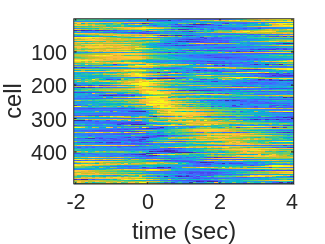

    imagesc(-before_event:0.1:after_event,1:size(trial_start_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_start_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = trial_end_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =    -0.5579   -0.9464   -0.3941   -0.5212   -0.6951   -0.4311   -0.1736   -0.2811   -0.4532   -0.2250    0.0028    0.0144   -0.1277    0.0333    0.3041    0.1988    0.1355    0.3145   -0.2016   -0.1363    0.3945   -0.1375   -0.3765   -0.2137   -0.4932   -0.8491   -0.7959   -0.7846   -0.7912   -1.1227   -1.4090   -0.8281   -1.3096   -1.5331   -0.8242   -1.1972   -0.8344   -1.1402   -0.3458   -0.0139   -0.2422   -0.0051   -0.5540   -0.0744    0.0035   -0.1778   -0.3461    0.0924    0.2969    0.4465
    0.7178    0.7288    0.7566    0.6490    0.6234    0.5922    0.6301    0.5785    0.4228    0.4231    0.1626    0.1074    0.0307   -0.0023   -0.0429   -0.2634   -0.1765   -0.3426   -0.3344   -0.3804   -0.2706   -0.2192   -0.3634   -0.5502   -0.4184   -0.5255   -0.7057   -0.7162   -0.9423   -0.9132   -1.1281   -1.0974   -1.2141   -1.3279   -1.4429   -1.4622   -1.3973   -1.2023   -1.1733   -1.4573   -1.3847   -1.1866   -0.9955   -1.0104   -0.6254   -0.4334    0.0788    0.3423    0.7249 

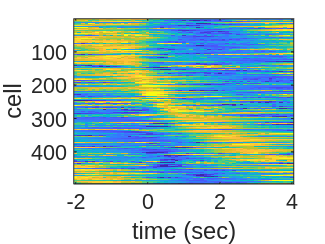

    imagesc(-before_event:0.1:after_event,1:size(trial_end_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_trial_end_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = position_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     0.6076    0.6760    0.3686    0.9695    0.8772    0.2841    0.1577    0.1036   -0.1706    0.2274    0.0937    0.5047    0.7299    0.6960    0.5692    0.9133    0.5251    0.4136    0.5448    0.7129    0.3870    0.6766    0.4700    0.1177   -0.1121   -0.4279   -0.4938   -0.6627   -1.1658   -1.0103   -1.3654   -1.5392   -1.7066   -1.6392   -1.7075   -1.8679   -1.8940   -1.6042   -1.6797   -1.6666   -1.1898   -0.9889   -1.0619   -0.8865   -0.7569   -0.3029    0.0265    0.4260    0.4498    0.4155
   -0.4544   -0.8473   -0.2544   -0.6358   -0.5160   -0.2393   -0.5220   -0.6234   -0.4719   -0.4228   -0.4099   -0.5127   -0.9337   -0.8270   -0.5716   -1.0222   -0.8787   -0.9593   -1.4067   -0.6148   -1.0228   -0.9424   -0.5717   -0.8893   -1.3178   -1.6287   -1.6259   -1.2478   -1.3915   -0.8160   -0.6233   -0.4595    0.4010    0.1113    0.5344    0.1972    1.1187    1.0566    1.3871    1.5025    1.3480    1.4147    2.0139    1.9439    1.7028    1.9527    1.3674    1.6415    1.2409 

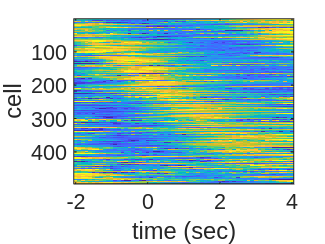

    imagesc(-before_event:0.1:after_event,1:size(position_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_position_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = force_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =     1.9723    1.7927    1.4710    1.5125    1.5464    1.3909    1.3572    1.1479    1.0064    1.0089    0.9902    0.8800    0.5515    0.4155    0.4209    0.1878    0.1150    0.0806   -0.2554   -0.3017   -0.5364   -0.8347   -1.0258   -1.1230   -1.4496   -1.1852   -1.3425   -1.3240   -1.4337   -1.2503   -1.3891   -1.2898   -1.1254   -1.3058   -1.1277   -1.0680   -1.0757   -1.1275   -1.1205   -0.7764   -0.9895   -0.7673   -0.5779   -0.4641   -0.3804   -0.2073   -0.0100    0.1700    0.2283    0.4001
    0.7155    0.6236    0.8391    0.8162    1.1952    1.3938    1.3088    1.3706    1.2105    1.2433    1.1207    0.9725    0.7081    0.8341    0.8416    0.6244    1.0517    0.9727    0.5010    0.6679    0.2138   -0.5015   -0.5565   -0.5713   -0.4490   -1.0283   -0.7740   -1.0394   -1.1750   -1.6084   -1.9877   -1.6809   -1.7159   -1.9106   -1.5588   -1.8218   -1.4286   -1.0102   -1.7072   -0.7193   -0.9538   -0.6813   -0.6325   -0.4156   -0.4290   -0.1373   -0.1960   -0.0017    0.1460 

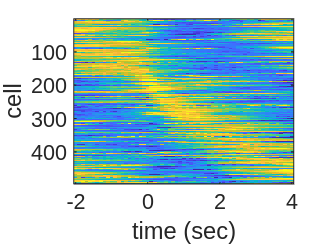

    imagesc(-before_event:0.1:after_event,1:size(force_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_force_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% climit = [0 50]
figure
set(gcf,'color','w');
% for i = 1:length(brain_roi) 
%     subaxis(length(brain_roi),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.03);
    clims = climit;
    image = reward_act_conc %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);

image =    -0.6099   -1.3781   -0.2116   -0.1936    0.2193    0.5328    0.4750   -0.1086   -0.2850   -0.0063    0.8476   -0.4239    1.1559    0.3013    0.4197    1.7472    2.8171    2.0113    2.7677    0.3539   -0.2322   -0.2347   -1.4006   -1.1223   -0.8993   -1.8988   -1.1778   -1.1373   -1.2705   -0.8840   -1.0148   -0.8971    0.4085   -1.2228   -0.6271    0.4369   -0.3255   -0.7124    0.1020   -0.1582   -1.2894   -0.2708   -1.0334   -0.3247   -1.1230   -0.7956    0.7828    0.8340    0.8143    1.4796
    0.3857    0.1219    0.2191    0.2991    0.2298    0.3016    0.1903    0.0891    0.0994    0.0253   -0.0461   -0.2102   -0.3801   -0.3993   -0.5431   -0.5844   -0.4748   -0.6886   -0.6225   -0.6775   -0.7303   -0.8068   -1.0321   -0.8889   -1.0476   -1.0382   -1.1423   -1.2151   -1.2509   -1.2302   -1.2789   -1.2569   -1.2941   -1.3238   -1.3217   -1.2543   -1.0725   -0.8786   -0.7372   -0.3034   -0.2039    0.2042    0.3489    0.5767    0.6314    0.8599    0.8948    1.0720    0.9914 

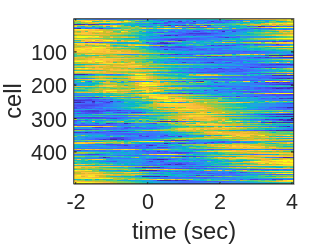

    imagesc(-before_event:0.1:after_event,1:size(reward_act_conc,1),image,clims);
    ylabel('cell');
    xlabel('time (sec)');
% end

filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_reward_eta_activity_heatmap.png'];
saveas(gcf,filename);

% close all;

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_actss_ordered{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);
        imagesc(-before_event:0.1:after_event,1:size(pull_actss_ordered{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;
    end
        
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_actss_ordered{i};
        data = data(~any(isnan(data), 2), :);

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);
        x = -before_event:0.1:after_event;
      
        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % xlim = [-2,4]
        % x=0に赤い縦線をプロット       
        % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 2]);
        end
    end
        
        filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity.png'];
        saveas(gcf,filename);
    % close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};

    figure('Position', [100, 100, 1600, 600]);
    for i = 1:4
        subaxis(1,4,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.08);
        % NaNを含む行を削除
        if i == 1
            data1 = pull_actss_ordered{1}; data2 = pull_actss_ordered{2};
        elseif i == 4
            data1 = pull_actss_ordered{3}; data2 = pull_actss_ordered{5};   
            data3 = pull_actss_ordered{4}; data4 = pull_actss_ordered{6};
        else
            data1 = pull_actss_ordered{i+1}; data2 = pull_actss_ordered{i+3};
        end
        data1 = data1(~any(isnan(data1), 2), :); data2 = data2(~any(isnan(data2), 2), :);    
        mean_values1 = mean(data1, 1); mean_values2 = mean(data2, 1);
        std_values1 = std(data1, 0, 1); std_values2 = std(data2, 1); 
        if i == 4
            data3 = data3(~any(isnan(data3), 2), :); data4 = data4(~any(isnan(data4), 2), :);    
            mean_values3 = mean(data3, 1); mean_values4 = mean(data4, 1);
            std_values3 = std(data3, 0, 1); std_values4 = std(data4, 1);             
        end
        x = -before_event:0.1:after_event;
      
        if i == 1
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'c', 'LineWidth', 1.5); 
        elseif i == 2
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
        elseif i == 3
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'c', 'LineWidth', 1.5); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'c', 'LineWidth', 1.5,'LineStyle', ':');             
        else
            % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
            % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
            % fill([x, fliplr(x)], [mean_values3 + std_values3, fliplr(mean_values3 - std_values3)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values3, 'c', 'LineWidth', 1.5); 
            % fill([x, fliplr(x)], [mean_values4 + std_values4, fliplr(mean_values4 - std_values4)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            plot(x, mean_values4, 'c', 'LineWidth', 1.5,'LineStyle', ':');            
        end
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 2]);
        end
        % ANOVAとTukeyテストを実施
        if i == 4
            perform_anova_tukey(data1, data2, data3, data4);
        else
            perform_anova_tukey(data1, data2, [], []);
        end            
    end

    
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_eta_activity_compare.png'];
    saveas(gcf,filename);
    % close all;
end

% % write eta code by categrizing neurons by layers
% if strcmp(categorize, 'layer') == 1
%     layer23_cells    = cell(1,length(Animal));
%     layer5_cells   = cell(1,length(Animal));
%     trial_start_act_layer23_cells    = cell(1,length(Animal));
%     trial_start_act_layer5_cells    = cell(1,length(Animal));
%     trial_end_act_layer23_cells    = cell(1,length(Animal));
%     trial_end_act_layer5_cells    = cell(1,length(Animal));
%     position_act_layer23_cells    = cell(1,length(Animal));
%     position_act_layer5_cells    = cell(1,length(Animal));
%     force_act_layer23_cells    = cell(1,length(Animal));
%     force_act_layer5_cells    = cell(1,length(Animal));
%     reward_act_layer23_cells    = cell(1,length(Animal));
%     reward_act_layer5_cells    = cell(1,length(Animal));
%     for i_animal = 1:length(Animal)
%         layer23_cells{i_animal} = acc_neural_activity_data{i_animal}(:,find(pointAreas{i_animal} == 1));
%         layer5_cells{i_animal}  = acc_neural_activity_data{i_animal}(:,find(pointAreas{i_animal} == 0));
% 
%         startAreas = cat(2,start_I{i_animal},pointAreas{i_animal});
%         startAreas = sortrows(startAreas);
%         startAreas(:,1) = [];
%         trial_start_act_layer23_cells{i_animal} = trial_start_act_multi_animals{i_animal}(find(startAreas == 1),:);
%         trial_start_act_layer5_cells{i_animal}  = trial_start_act_multi_animals{i_animal}(find(startAreas == 0),:);
% 
%         endAreas = cat(2,end_I{i_animal},pointAreas{i_animal});
%         endAreas = sortrows(endAreas);
%         endAreas(:,1) = [];
%         trial_end_act_layer23_cells{i_animal} = trial_end_act_multi_animals{i_animal}(find(endAreas == 1),:);
%         trial_end_act_layer5_cells{i_animal} = trial_end_act_multi_animals{i_animal}(find(endAreas == 0),:);
% 
%         posAreas = cat(2,pos_I{i_animal},pointAreas{i_animal});
%         posAreas = sortrows(posAreas);
%         posAreas(:,1) = [];
%         position_act_layer23_cells{i_animal} = position_act_multi_animals{i_animal}(find(posAreas == 1),:);
%         position_act_layer5_cells{i_animal}  = position_act_multi_animals{i_animal}(find(posAreas == 0),:);
% 
%         forceAreas = cat(2,force_I{i_animal},pointAreas{i_animal});
%         forceAreas = sortrows(forceAreas);
%         forceAreas(:,1) = [];
%         force_act_layer23_cells{i_animal} = force_act_multi_animals{i_animal}(find(forceAreas == 1),:);
%         force_act_layer5_cells{i_animal}  = force_act_multi_animals{i_animal}(find(forceAreas == 0),:);
% 
%         rewardAreas = cat(2,reward_I{i_animal},pointAreas{i_animal});
%         rewardAreas = sortrows(rewardAreas);
%         rewardAreas(:,1) = [];
%         reward_act_layer23_cells{i_animal} = reward_act_multi_animals{i_animal}(find(rewardAreas == 1),:);
%         reward_act_layer5_cells{i_animal}  = reward_act_multi_animals{i_animal}(find(rewardAreas == 0),:);
%     end
% end

% if categorize == 'layer'
%     trial_start_act_layer23_conc = trial_start_act_layer23_cells{1};
%     trial_end_act_layer23_conc   = trial_end_act_layer23_cells{1};
%     position_act_layer23_conc    = position_act_layer23_cells{1};
%     force_act_layer23_conc       = force_act_layer23_cells{1};
%     reward_act_layer23_conc      = reward_act_layer23_cells{1};
%     trial_start_act_layer5_conc = trial_start_act_layer5_cells{1};
%     trial_end_act_layer5_conc   = trial_end_act_layer5_cells{1};
%     position_act_layer5_conc    = position_act_layer5_cells{1};
%     force_act_layer5_conc       = force_act_layer5_cells{1};
%     reward_act_layer5_conc      = reward_act_layer5_cells{1};
%     for i_animal = 2:length(Animal)
%         trial_start_act_conc = vertcat(trial_start_act_conc, trial_start_act_multi_animals{i_animal});
%         trial_end_act_conc = vertcat(trial_end_act_conc, trial_end_act_multi_animals{i_animal});
%         position_act_conc = vertcat(position_act_conc, position_act_multi_animals{i_animal});
%         force_act_conc = vertcat(force_act_conc, force_act_multi_animals{i_animal});
%         reward_act_conc = vertcat(reward_act_conc, reward_act_multi_animals{i_animal});
%         trial_start_act_layer23_conc = vertcat(trial_start_act_layer23_conc, trial_start_act_layer23_cells{i_animal});
%         trial_end_act_layer23_conc   = vertcat(trial_end_act_layer23_conc, trial_end_act_layer23_cells{i_animal});
%         position_act_layer23_conc    = vertcat(position_act_layer23_conc, position_act_layer23_cells{i_animal});
%         force_act_layer23_conc       = vertcat(force_act_layer23_conc, force_act_layer23_cells{i_animal});
%         reward_act_layer23_conc      = vertcat(reward_act_layer23_conc, reward_act_layer23_cells{i_animal});
%         trial_start_act_layer5_conc = vertcat(trial_start_act_layer5_conc, trial_start_act_layer5_cells{i_animal});
%         trial_end_act_layer5_conc   = vertcat(trial_end_act_layer5_conc, trial_end_act_layer5_cells{i_animal});
%         position_act_layer5_conc    = vertcat(position_act_layer5_conc, position_act_layer5_cells{i_animal});
%         force_act_layer5_conc       = vertcat(force_act_layer5_conc, force_act_layer5_cells{i_animal});
%         reward_act_layer5_conc      = vertcat(reward_act_layer5_conc, reward_act_layer5_cells{i_animal});
%     end
% end

% % plot layer23 neural activity
% % plot neural activity heatmap
% if strcmp(categorize, 'layer') == 1
%     climit = [0 50]
%     figure
%     set(gcf,'color','w');
%     for i = 1:length(Animal) 
%         subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
%         clims = climit;
%         image = transpose(layer23_cells{i})
%     %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
%         imagesc(0:0.1:(size(layer23_cells{i},1)-1)/10,1:size(layer23_cells{i},2),image,clims);
%     %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
%         ylabel('cell');
%         xlabel('time (sec)');
%     end
% 
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_' strrep(strjoin(uniqueAnimal),' ','_') '_layer23_activity_heatmap.png'];
%     saveas(gcf,filename);
%     close all;
% end

% if strcmp(categorize, 'layer') == 1
%     addpath([working_directory 'Utility' filesep 'Subaxis']);
%     example_num = 5;
%     display_start = 1; %113;
%     ylimit=[0 150];
%     figure
%     for j = 1:length(Animal)
%         for i = 1:example_num
%             subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%             b = plot(0:0.1:(size(layer23_cells{j},1)-1)/10,layer23_cells{j}(:,display_start+i));
%         %     title([brain_roi_name(i)], 'FontSize',6);
%             ylim(ylimit); 
%             xlim([0 (size(layer23_cells{j},1)-1)/10]);
%         %     ylabel('neural activity');
%         %     xlabel('time (sec)')
%         end
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_exmple_activity_traces.png'];
%     saveas(gcf,filename);
%     end
% end

% % plot layer5 neural activity
% % plot neural activity heatmap
% if strcmp(categorize, 'layer') == 1
%     climit = [0 50];
%     figure
%     set(gcf,'color','w');
%     for i = 1:length(Animal) 
%         subaxis(length(Animal),1,i, 'Spacing', 0.06, 'Padding', 0, 'Margin', 0.06);
%         clims = climit;
%         image = transpose(layer5_cells{i})
%     %     image = transpose(acc_neural_activity_data(1:100,:)) %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
%         imagesc(0:0.1:(size(layer5_cells{i},1)-1)/10,1:size(layer5_cells{i},2),image,clims);
%     %     imagesc(0:0.1:10,1:size(acc_neural_activity_data,2),image,clims);
%         ylabel('cell');
%         xlabel('time (sec)')
%     end
% 
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_activity_heatmap.png'];
%     saveas(gcf,filename);
%     close all;
% end

% if strcmp(categorize, 'layer') == 1
%     addpath([working_directory 'Utility' filesep 'Subaxis']);
%     example_num = 0;
%     display_start = 0; %113;
%     ylimit=[0 150];
%     figure
%     for j = 1:length(Animal)
%         for i = 1:example_num
%             subaxis(example_num,length(Animal),2*i+j-2, 'Spacing', 0.06, 'Padding', 0.01, 'Margin', 0.03);
%             b = plot(0:0.1:(size(layer5_cells{j},1)-1)/10,layer5_cells{j}(:,display_start+i));
%         %     title([brain_roi_name(i)], 'FontSize',6);
%             ylim(ylimit); 
%             xlim([0 (size(layer5_cells{j},1)-1)/10]);
%         %     ylabel('neural activity');
%         %     xlabel('time (sec)')
%         end
%     filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_exmple_activity_traces.png'];
%     saveas(gcf,filename);
%     end
% end

% plot layer specific eta by multiple plane figure
if strcmp(categorize, 'layer') == 1
    if norm == 1
        climit = [0 1];
    elseif norm == 2 | norm == 3 | norm == 4 | norm == 5
        climit = [-2 2];
    elseif norm == 6
        climit = [-4 4];
    % else
    %     climit = [0 50];
    end
    
    layer23_act = {trial_start_act_layer23_conc, trial_end_act_layer23_conc, position_act_layer23_conc, force_act_layer23_conc, reward_act_layer23_conc};
    layer5_act  = {trial_start_act_layer5_conc, trial_end_act_layer5_conc, position_act_layer5_conc, force_act_layer5_conc, reward_act_layer5_conc};
    title_list = {'Trial start', 'Trial end', 'Position', 'Force', 'Reward'};
    figure
    set(gcf,'color','w');

    for i = 1:length(layer23_act) 
        subaxis(1,length(layer23_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer23_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer23_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     xlabel('time (sec)');
   
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
    
    figure
    set(gcf,'color','w');
    for i = 1:length(layer5_act) 
        subaxis(1,length(layer5_act),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = layer5_act{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        imagesc(-before_event:0.1:after_event,1:size(layer5_act(i),1),image,clims);
%         ylabel('cell');
        xlabel('time (sec)');
        if i == 1
            ylabel('cell');
        end
        title(title_list{i});
    end
%     ylabel('cell');
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
%     close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
    % pull_act_layer23_cells   = cell(0,length(AlinmentTimingCells));
    % pull_act_layer5_cells    = cell(0,length(AlinmentTimingCells));
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};
    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer23_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer23_cells{i},1),image,clims);
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;           
    end
        
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer23_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_act_layer23_cells{i};
        data = data(~any(isnan(data), 2), :);

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);      
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end      
        hold off;
        axis tight;  
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 2]);
        end
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
        
    end
        
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer23_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    set(gcf,'color','w');
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        clims = climit;
        image = pull_act_layer5_cells{i}; %reshape(roi_activities(i,:,:),[size(roi_activities,2), size(roi_activities,3)]);
        % NaNを含む行を削除
        image = image(~any(isnan(image), 2), :);        
        imagesc(-before_event:0.1:after_event,1:size(pull_act_layer5_cells{i},1),image,clims);
        % x=0 に白い縦線を描画
        hold on; % プロットを追加するために hold on を使用
        yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
        plot([0 0], yLimits, 'w-', 'LineWidth', 1); % x=0 に白い縦線を描画
        hold off;          
        if i == 1
            ylabel('cell');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer5_eta_activity_heatmap.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data = pull_act_layer5_cells{i};
        data = data(~any(isnan(data), 2), :);

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);              
        x = -before_event:0.1:after_event;

        fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        hold on;
        plot(x, mean_values, 'b', 'LineWidth', 1.5); 
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end       
        hold off;
        axis tight;          
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 2]);
        end     
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer5_eta_activity.png'];
    saveas(gcf,filename);
    % close all;

    figure('Position', [100, 100, 2400, 600]);
    for i = 1:length(AlinmentTimingCells)
        subaxis(1,length(AlinmentTimingCells),i, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
        % NaNを含む行を削除
        data23 = pull_act_layer23_cells{i};
        data23 = data23(~any(isnan(data23), 2), :);
        data5 = pull_act_layer5_cells{i};
        data5 = data5(~any(isnan(data5), 2), :);        

        mean_values = mean(data, 1);
        std_values = std(data, 0, 1);              
        mean_values23 = mean(data23, 1);
        std_values23 = std(data23, 0, 1);        
        mean_values5 = mean(data5, 1);
        std_values5 = std(data5, 0, 1);
        x = -before_event:0.1:after_event;

        hold on;        
        fill([x, fliplr(x)], [mean_values23 + std_values23, fliplr(mean_values23 - std_values23)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values23, 'g', 'LineWidth', 1.5); 
        fill([x, fliplr(x)], [mean_values5 + std_values5, fliplr(mean_values5 - std_values5)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        plot(x, mean_values5, 'b', 'LineWidth', 1.5);         
        % x=0に赤い縦線をプロット
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end        
        hold off;
        axis tight;  
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 2]);
        end      
        if i == 1
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});
    end
        
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer235_eta_activity.png'];
    saveas(gcf,filename);
    % close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    title_list = {'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};

    figure('Position', [100, 100, 1600, 600]);
    for i = 1:4
        subaxis(1,4,i, 'Spacing', 0.04, 'Padding', 0.02, 'Margin', 0.08);
        % NaNを含む行を削除
        if i == 1
            data1 = pull_act_layer23_cells{1}; data2 = pull_act_layer23_cells{2};
            data11 = pull_act_layer5_cells{1}; data21 = pull_act_layer5_cells{2};            
        elseif i == 4
            data1 = pull_act_layer23_cells{3}; data2 = pull_act_layer23_cells{5};   
            data3 = pull_act_layer23_cells{4}; data4 = pull_act_layer23_cells{6};
            data11 = pull_act_layer5_cells{3}; data21 = pull_act_layer5_cells{5};   
            data31 = pull_act_layer5_cells{4}; data41 = pull_act_layer5_cells{6};            
        else
            data1 = pull_act_layer23_cells{i+1}; data2 = pull_act_layer23_cells{i+3};
            data11 = pull_act_layer5_cells{i+1}; data21 = pull_act_layer5_cells{i+3};            
        end
        data1 = data1(~any(isnan(data1), 2), :); data2 = data2(~any(isnan(data2), 2), :);
        data11 = data11(~any(isnan(data11), 2), :); data21 = data21(~any(isnan(data21), 2), :);         
        mean_values1 = mean(data1, 1); mean_values2 = mean(data2, 1);
        std_values1 = std(data1, 0, 1); std_values2 = std(data2, 1);
        mean_values11 = mean(data11, 1); mean_values21 = mean(data21, 1);
        std_values11 = std(data11, 0, 1); std_values21 = std(data21, 1);         
        if i == 4
            data3 = data3(~any(isnan(data3), 2), :); data4 = data4(~any(isnan(data4), 2), :); 
            data31 = data31(~any(isnan(data31), 2), :); data41 = data41(~any(isnan(data41), 2), :);             
            mean_values31 = mean(data31, 1); mean_values41 = mean(data41, 1);
            std_values31 = std(data31, 0, 1); std_values41 = std(data41, 1);             
        end
        x = -before_event:0.1:after_event;
      
        if i == 1
            hold on;
            plot(x, mean_values1,  'Color', [0 0.5 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0.5 1 0], 'LineWidth', 1.5); 
            plot(x, mean_values11, 'b', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'c', 'LineWidth', 1.5);             
        elseif i == 2
            hold on;
            plot(x, mean_values1, 'Color', [0 0.5 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0 0.5 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values11, 'b', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'b', 'LineWidth', 1.5,'LineStyle', ':');            
        elseif i == 3
            hold on;
            plot(x, mean_values1, 'Color', [0.5 1 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0.5 1 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values11, 'c', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'c', 'LineWidth', 1.5,'LineStyle', ':');               
        else
            hold on;
            plot(x, mean_values1, 'Color', [0 0.5 0], 'LineWidth', 1.5); 
            plot(x, mean_values2, 'Color', [0 0.5 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values3, 'Color', [0.5 1 0], 'LineWidth', 1.5); 
            plot(x, mean_values4, 'Color', [0.5 1 0], 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values11, 'b', 'LineWidth', 1.5); 
            plot(x, mean_values21, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
            plot(x, mean_values31, 'c', 'LineWidth', 1.5); 
            plot(x, mean_values41, 'c', 'LineWidth', 1.5,'LineStyle', ':');             
        end
        if norm ~= 0
            plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
        else
            yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
        end
        hold off;
        if i == 1;
            ylabel('normalized activity');
        end
        xlabel('time (sec)');
        title(title_list{i});        
         axis tight;
        if norm ~= 0 & norm ~= 6
            ylim([-1 1]);  
        elseif norm == 6
            ylim([-1 2]);
        end
    end
        
        filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_pull_layer235_eta_activity_compare.png'];
        saveas(gcf,filename);
    % close all;
end


% 階層的クラスタリングの実施

if Kota_alignment == 1
    % NaNを含む行を削除
    data = pull_actss{length(AlinmentTimingCells)+1};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_hierarchical_clustering_dendrogram.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_elbow.png'];
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_eta_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
end

% plot clustered ETA neural activity
if Kota_alignment == 1
    num_clusters = 5; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    all_cluster_labels = cluster_labels;
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end

    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};

    fig_y = 600*num_clusters;
    % figure('Position', [100, 100, fig_y, 2400]);
    figure('Position', [100, 100, 2400, fig_y]);    
    for i = 1:length(AlinmentTimingCells)
        % NaNを含む行を削除
        i_data = pull_actss{i};
        i_data = i_data(~any(isnan(data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters   
            % subaxis(num_clusters,length(AlinmentTimingCells),(i-1)*length(AlinmentTimingCells)+cluster_num, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            subaxis(num_clusters,length(AlinmentTimingCells),i+length(AlinmentTimingCells)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'b', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 12]);
            end
        end
    end
        
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_eta_activity.png'];
    saveas(gcf,filename);
    % close all;
end

% Plot ETA heatmap of Kota (pull) timing alignment of each condition
% AlinmentTimingCells
if Kota_alignment == 1
    title_list = {'Heavy - Light', 'Exp heavy - Unexp heavy', 'Exp light - Unexp light', 'Exp heavy - Unexp heavy - Exp light - Unexp light'};
    fig_y = 400*num_clusters;
    % fig_y = 600*num_clusters;
    figure('Position', [100, 100, fig_y, 2400]);
    % figure('Position', [100, 100, 1600, fig_y]);
    for i = 1:4
        % NaNを含む行を削除
        if i == 1
            data1 = pull_actss{1}; data2 = pull_actss{2};
        elseif i == 4
            data1 = pull_actss{3}; data2 = pull_actss{5};   
            data3 = pull_actss{4}; data4 = pull_actss{6};
        else
            data1 = pull_actss{i+1}; data2 = pull_actss{i+3};
        end        
        % i_data = pull_actss{i};
        % i_data = i_data(~any(isnan(data), 2), :);

        for cluster_num = 1:num_clusters
            subaxis(4,num_clusters,(i-1)*num_clusters+cluster_num, 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);            
            % subaxis(num_clusters,4,i+4*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data1 = data1(cluster_labels == cluster_num, :); cluster_data2 = data2(cluster_labels == cluster_num, :);
            cluster_data1 = cluster_data1(~any(isnan(cluster_data1), 2), :); cluster_data2 = cluster_data2(~any(isnan(cluster_data2), 2), :);

            mean_values1 = mean(cluster_data1, 1); mean_values2 = mean(cluster_data2, 1);
            std_values1 = std(cluster_data1, 0, 1); std_values2 = std(cluster_data2, 0, 1);
            if i == 4
                cluster_data3 = data3(cluster_labels == cluster_num, :); cluster_data4 = data4(cluster_labels == cluster_num, :);
                cluster_data3 = cluster_data3(~any(isnan(cluster_data3), 2), :); cluster_data4 = cluster_data4(~any(isnan(cluster_data4), 2), :);   
                mean_values3 = mean(cluster_data3, 1); mean_values4 = mean(cluster_data4, 1);
                std_values3 = std(cluster_data3, 0, 1); std_values4 = std(cluster_data4, 0, 1);           
            end            
            x = -before_event:0.1:after_event;
          
            % fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            % hold on;
            % plot(x, mean_values, 'b', 'LineWidth', 1.5); 
            if i == 1
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values2, 'c', 'LineWidth', 1.5); 
            elseif i == 2
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
            elseif i == 3
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'c', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values2, 'c', 'LineWidth', 1.5,'LineStyle', ':');             
            else
                % fill([x, fliplr(x)], [mean_values1 + std_values1, fliplr(mean_values1 - std_values1)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                hold on;
                plot(x, mean_values1, 'b', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values2 + std_values2, fliplr(mean_values2 - std_values2)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values2, 'b', 'LineWidth', 1.5,'LineStyle', ':'); 
                % fill([x, fliplr(x)], [mean_values3 + std_values3, fliplr(mean_values3 - std_values3)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values3, 'c', 'LineWidth', 1.5); 
                % fill([x, fliplr(x)], [mean_values4 + std_values4, fliplr(mean_values4 - std_values4)], 'c', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
                plot(x, mean_values4, 'c', 'LineWidth', 1.5,'LineStyle', ':');            
            end            
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if cluster_num == 1
            % if i == 1
                ylabel('normalized activity');
            end
            if i == 4
            % if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            % if cluster_num == 1
            %     title(title_list{i});
            % end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 12]);
            end
        end
    end
        
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_eta_activity_compare.png'];
    saveas(gcf,filename);
    % close all;
end

% Layer23 階層的クラスタリングの実施

if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    % NaNを含む行を削除
    data = pull_act_layer23_cells{length(AlinmentTimingCells)+1};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_hierarchical_clustering_dendrogram.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_elbow.png'];
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer23_eta_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
end

% plot clustered ETA neural activity
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    num_clusters = 3; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end

    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};

    fig_y = 600*num_clusters;
    figure('Position', [100, 100, 2400, fig_y]);
    for i = 1:length(AlinmentTimingCells)
        % NaNを含む行を削除
        i_data = pull_act_layer23_cells{i};
        i_data = i_data(~any(isnan(data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters
            subaxis(num_clusters,length(AlinmentTimingCells),i+length(AlinmentTimingCells)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'g', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'g', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 12]);
            end
        end
    end
        
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_layer23_eta_activity.png'];
    saveas(gcf,filename);
    % close all;
end

% Layer5 階層的クラスタリングの実施

if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    % NaNを含む行を削除
    data = pull_act_layer5_cells{length(AlinmentTimingCells)+1};
    data = data(~any(isnan(data), 2), :);
    % 階層的クラスタリングを使用して細胞の順序を変更（Ward法）
    linkage_matrix = linkage(data, 'ward');
    
    % 樹形図の作成
    figure('Position', [100, 100, 800, 600]);
    [H, T, outperm] = dendrogram(linkage_matrix, 0);%, 'Reorder', 'true');
    % title(title_list{i}); %'Hierarchical Clustering Dendrogram (Ward)');
    xlabel('Cell');
    ylabel('Distance');
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_hierarchical_clustering_dendrogram.png'];
    saveas(gcf,filename);    
    
    % 順序付けされたdata
    ordered_data = data(outperm, :);
    
    % エルボー法のためのプロット作成
    figure('Position', [100, 100, 800, 600]);
    last = linkage_matrix(end-9:end, 3);
    last_rev = flipud(last);
    indexes = 1:length(last);
    hold on
    plot(indexes, last_rev, 'b-o');
    acceleration = diff(last, 2);  % 2次の微分を計算
    acceleration_rev = zeros(10,1);
    acceleration_rev(2:end-1) = flipud(acceleration);
    plot(indexes, acceleration_rev, 'r-o');
    hold off
    xlabel('Number of clusters');
    ylabel('Distance');
    % title(title_list{i}); %title('Elbow Method for Optimal Number of Clusters');
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_elbow.png'];
    saveas(gcf,filename);     
    
    % 相関行列の表示
    figure('Position', [100, 100, 800, 600]);
    imagesc(ordered_data, [0 1]);
    colorbar;
    % title(title_list{i});  %title('Correlation Matrix');
    xlabel('Cell');
    ylabel('Time (sec)');
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer5_eta_heatmap2.png'];
    saveas(gcf,filename);         
        % colormap('viridis');
    % end
end

% plot clustered ETA neural activity
if strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    num_clusters = 2; % クラスター数を指定（必要に応じて変更）
    % クラスタリングの実行
    cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
    unique_elements = unique(cluster_labels);
    counts = histc(cluster_labels, unique_elements);
    for n = 1:length(unique_elements)
        fprintf('Element %d: %d cells\n', unique_elements(n),counts(n));
    end

    title_list = {'All heavy', 'All light', 'Exp heavy', 'Exp light', 'Unexp heavy','Unexp light'};

    fig_y = 600*num_clusters;
    figure('Position', [100, 100, 2400, fig_y]);
    for i = 1:length(AlinmentTimingCells)
        % NaNを含む行を削除
        i_data = pull_act_layer5_cells{i};
        i_data = i_data(~any(isnan(data), 2), :);
        % % hierarchical clustering
        % linkage_matrix = linkage(data, 'ward');
        % % クラスタリングの実行
        % cluster_labels = cluster(linkage_matrix, 'maxclust', num_clusters);
        for cluster_num = 1:num_clusters
            subaxis(num_clusters,length(AlinmentTimingCells),i+length(AlinmentTimingCells)*(cluster_num-1), 'Spacing', 0.04, 'Padding', 0, 'Margin', 0.08);
            
            cluster_data = i_data(cluster_labels == cluster_num, :);
            cluster_data = cluster_data(~any(isnan(cluster_data), 2), :);

            mean_values = mean(cluster_data, 1);
            std_values = std(cluster_data, 0, 1);
            x = -before_event:0.1:after_event;
          
            fill([x, fliplr(x)], [mean_values + std_values, fliplr(mean_values - std_values)], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
            hold on;
            plot(x, mean_values, 'b', 'LineWidth', 1.5); 
            % xlim = [-2,4]
            % x=0に赤い縦線をプロット       
            % yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
            if norm ~= 0
                plot([0 0], [-100,100], 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画     
            else
                yLimits = get(gca, 'YLim'); % Y軸の範囲を取得
                plot([0 0], yLimits, 'r-', 'LineWidth', 1); % x=0 に赤い縦線を描画
            end
            hold off;
            if i == 1
                ylabel('normalized activity');
            end
            if cluster_num == num_clusters
                xlabel('time (sec)');
            end
            if cluster_num == 1
                title(title_list{i});
            end
             axis tight;
            if norm ~= 0 & norm ~= 6
                ylim([-2 2]);  
            elseif norm == 6
                ylim([-6 12]);
            end
        end
    end
        
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_clustered_pull_layer5_eta_activity.png'];
    saveas(gcf,filename);
    % close all;
end

% check the ratio of cells in each layer in each cluster
% all_cluster_labels
% pointAreas_conc

unique_pairs = unique([all_cluster_labels, pointAreas_conc], 'rows');

関数または変数 'all_cluster_labels' が認識されません。

counts = zeros(size(unique_pairs, 1), 1);

for i = 1:size(unique_pairs, 1)
    counts(i) = sum(ismember([all_cluster_labels, pointAreas_conc], unique_pairs(i, :), 'rows'));
end

for i = 1:size(unique_pairs, 1)
    fprintf('Pair (%d, %d): %d times\n', unique_pairs(i, 1), unique_pairs(i, 2), counts(i));
end


% ユニークな要素を見つける
unique_list2 = unique(pointAreas_conc);

% Figureの作成
figure('Position', [100, 100, 2400, 600]);

% 各カテゴリーごとにプロット
num_categories = length(unique_list2);
for i = 1:num_categories
    category = unique_list2(i);
    indices = pointAreas_conc == category;
    subset_list1 = all_cluster_labels(indices);
    
    % List1のカテゴリーの割合を計算
    unique_subset_list1 = unique(subset_list1);
    counts = histc(subset_list1, unique_subset_list1);
    percentages = counts / sum(counts) * 100;
    
    % 円グラフをプロット
    subplot(1, num_categories, i);
    % pie(percentages, arrayfun(@num2str, unique_subset_list1, 'UniformOutput', false));
    pie(percentages, arrayfun(@(x) [num2str(counts(x == unique_subset_list1)) ' - ' num2str(round(percentages(x == unique_subset_list1), 2)) '%'], unique_subset_list1, 'UniformOutput', false));
    legend(arrayfun(@num2str, unique_subset_list1, 'UniformOutput', false), 'Location', 'southoutside', 'Orientation', 'horizontal');    
    if category == 0
        title(['Layer 5']);
    else
        title(['Layer 23']);
    end
end

filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer235_cluster_percentage.png'];
saveas(gcf,filename);

% plot ratio of significantly activated cells
if norm == 3 & Kota_alignment == 1
    %Actual resistance cell ratio
    % テキストファイルのオープン
    txtname = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_sig_cell_ratio.txt'];
    fileID = fopen(txtname, 'w');
    % Figureの作成
    figure('Position', [100, 100, 2400, 600]);
    legend({'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'}, 'Location', 'eastoutside'); 
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    h_sig_idxs = pull_sig_cell_idxs{1};
    l_sig_idxs = pull_sig_cell_idxs{2};
    for i_sig = 1:size(pull_sig_cell_idxs{1},1)
        h_sig_idx = h_sig_idxs(i_sig,:);
        l_sig_idx = l_sig_idxs(i_sig,:);
        
        % 組み合わせの個数をカウント
        both_one = sum(h_sig_idx == 1 & l_sig_idx == 1);
        h_one_l_zero = sum(h_sig_idx == 1 & l_sig_idx == 0);
        h_zero_l_one = sum(h_sig_idx == 0 & l_sig_idx == 1);
        both_zero = sum(h_sig_idx == 0 & l_sig_idx == 0);
               
        % 円グラフ用のデータ
        total = length(h_sig_idx);
        data = [both_one, h_one_l_zero, h_zero_l_one, both_zero]; %/length(h_sig_idx)*100;
        % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};

        % % 円グラフ用のラベル
        % labels = {
        %     ['Heavy and light pull: ', num2str(both_one), ' (', num2str(both_one / total * 100, '%.2f'), '%)'], ...
        %     ['Heavy pull: ', num2str(h_one_l_zero), ' (', num2str(h_one_l_zero / total * 100, '%.2f'), '%)'], ...
        %     ['Light pull: ', num2str(h_zero_l_one), ' (', num2str(h_zero_l_one / total * 100, '%.2f'), '%)'], ...
        %     ['Neither: ', num2str(both_zero), ' (', num2str(both_zero / total * 100, '%.2f'), '%)']
        % };
        % カウントの結果をテキストファイルに書き込む
        fprintf(fileID, 'Signal %d\n', i_sig);
        fprintf(fileID, 'Heavy and light pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
        fprintf(fileID, 'Heavy pull: %d (%.2f%%)\n', h_one_l_zero, h_one_l_zero / total * 100);
        fprintf(fileID, 'Light pull: %d (%.2f%%)\n', h_zero_l_one, h_zero_l_one / total * 100);
        fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
        fprintf(fileID, '\n');        
        
        % 円グラフのプロット
        subplot(1, size(pull_sig_cell_idxs{1},1), i_sig);      
        pie(data, {'', '', '', ''});
        colormap([0 0 0; 0 0 1; 0 1 1; 0.5 0.5 0.5]); % 黒、濃い青、水色、灰色
        title(title_list{i_sig});        
    end   
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_actual_res_sig_cell_ratio.png'];
    saveas(gcf,filename);
    % Resistance Expected vs Unexpected cell ratio
    % Figureの作成
    figure('Position', [100, 100, 2400, 600]);
    legend({'Expected and unexpected pull', 'Expected pull', 'Unexpected pull', 'Neither'}, 'Location', 'eastoutside');     
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    e_sig_idxs = pull_sig_cell_idxs{3} | pull_sig_cell_idxs{4};
    u_sig_idxs = pull_sig_cell_idxs{5} | pull_sig_cell_idxs{6};
    for i_sig = 1:size(pull_sig_cell_idxs{1},1)
        e_sig_idx = e_sig_idxs(i_sig,:);
        u_sig_idx = u_sig_idxs(i_sig,:);
        
        % 組み合わせの個数をカウント
        both_one = sum(e_sig_idx == 1 & u_sig_idx == 1);
        e_one_u_zero = sum(e_sig_idx == 1 & u_sig_idx == 0);
        e_zero_u_one = sum(e_sig_idx == 0 & u_sig_idx == 1);
        both_zero = sum(e_sig_idx == 0 & u_sig_idx == 0);
        
        % 円グラフ用のデータ
        total = length(e_sig_idx);
        data = [both_one, e_one_u_zero, e_zero_u_one, both_zero]; %/length(e_sig_idx)*100;
        % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};
    
        % カウントの結果をテキストファイルに書き込む
        fprintf(fileID, 'Signal %d\n', i_sig);
        fprintf(fileID, 'Expected and unexpected pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
        fprintf(fileID, 'Expected pull: %d (%.2f%%)\n', e_one_u_zero, e_one_u_zero / total * 100);
        fprintf(fileID, 'Unexpected pull: %d (%.2f%%)\n', e_zero_u_one, e_zero_u_one / total * 100);
        fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
        fprintf(fileID, '\n');          
        
        % 円グラフのプロット
        subplot(1, size(pull_sig_cell_idxs{1},1), i_sig);      
        pie(data, {'', '', '', ''}); 
        colormap([0 0 0; 0 0.5 0; 0.5 1 0; 0.5 0.5 0.5]); % 黒、緑、淡い緑、灰色
        title(title_list{i_sig});
    end    
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_expect_res_sig_cell_ratio.png'];
    saveas(gcf,filename);

    % テキストファイルのクローズ
    fclose(fileID);    
end

% plot ratio of significantly activated cells
if norm == 3 & strcmp(categorize, 'layer') == 1 & Kota_alignment == 1
    %Actual resistance cell ratio
    % ユニークな要素を見つける
    unique_list2 = unique(pointAreas_conc);
    % 各カテゴリーごとにプロット
    num_categories = length(unique_list2);  
    % テキストファイルのオープン
    txtname = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_layer_sig_cell_ratio.txt'];
    fileID = fopen(txtname, 'w');    
    % Figureの作成
    figure('Position', [100, 100, 2400, 1200]);
    legend({'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'}, 'Location', 'eastoutside');     
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    h_sig_idxs = pull_sig_cell_idxs{1};h_sig_idxs_ori = pull_sig_cell_idxs{1};
    l_sig_idxs = pull_sig_cell_idxs{2};l_sig_idxs_ori = pull_sig_cell_idxs{2};
    for i = 1:num_categories
        category = unique_list2(i);
        indices = pointAreas_conc == category;
        h_sig_idxs = h_sig_idxs_ori(:,indices);
        l_sig_idxs = l_sig_idxs_ori(:,indices);
        for i_sig = 1:size(pull_sig_cell_idxs{1},1)
            h_sig_idx = h_sig_idxs(i_sig,:);
            l_sig_idx = l_sig_idxs(i_sig,:);
            
            % 組み合わせの個数をカウント
            both_one = sum(h_sig_idx == 1 & l_sig_idx == 1);
            h_one_l_zero = sum(h_sig_idx == 1 & l_sig_idx == 0);
            h_zero_l_one = sum(h_sig_idx == 0 & l_sig_idx == 1);
            both_zero = sum(h_sig_idx == 0 & l_sig_idx == 0);
   
            % 円グラフ用のデータ
            total = length(h_sig_idx);
            data = [both_one, h_one_l_zero, h_zero_l_one, both_zero]; %/length(h_sig_idx)*100;
            % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};
    
            % カウントの結果をテキストファイルに書き込む
            fprintf(fileID, 'Layer %d\n', i);
            fprintf(fileID, 'Signal %d\n', i_sig);
            fprintf(fileID, 'Heavy and light pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
            fprintf(fileID, 'Heavy pull: %d (%.2f%%)\n', h_one_l_zero, h_one_l_zero / total * 100);
            fprintf(fileID, 'Light pull: %d (%.2f%%)\n', h_zero_l_one, h_zero_l_one / total * 100);
            fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
            fprintf(fileID, '\n');              
            
            % 円グラフのプロット
            subplot(2, size(pull_sig_cell_idxs{1},1), (i-1)*7+i_sig);      
            pie(data, {'', '', '', ''});           
            colormap([0 0 0; 0 0 1; 0 1 1; 0.5 0.5 0.5]); % 黒、濃い青、水色、灰色
            % title(title_list{i_sig});
            if category == 0
                title(['Layer 5',title_list{i_sig}]);
            else
                title(['Layer 23',title_list{i_sig}]);
            end
        end
    end
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_actual_res_layer_sig_cell_ratio.png'];
    saveas(gcf,filename);    
    % Resistance Expected vs Unexpected cell ratio
    % Figureの作成
    figure('Position', [100, 100, 2400, 1200]);
    legend({'Expected and unexpected pull', 'Expected pull', 'Unexpected pull', 'Neither'}, 'Location', 'eastoutside');     
    title_list = [{'All activated','After activated','After deactivated','Before activated', 'Before deactivated', 'Surprise activated', 'Surprise deactivated'}];
    e_sig_idxs = pull_sig_cell_idxs{3} | pull_sig_cell_idxs{4};e_sig_idxs_ori = pull_sig_cell_idxs{3} | pull_sig_cell_idxs{4};
    u_sig_idxs = pull_sig_cell_idxs{5} | pull_sig_cell_idxs{6};u_sig_idxs_ori = pull_sig_cell_idxs{5} | pull_sig_cell_idxs{6};
    for i = 1:num_categories
        category = unique_list2(i);
        indices = pointAreas_conc == category;
        e_sig_idxs = e_sig_idxs_ori(:,indices);
        u_sig_idxs = u_sig_idxs_ori(:,indices);
        for i_sig = 1:size(pull_sig_cell_idxs{1},1)
            e_sig_idx = e_sig_idxs(i_sig,:);
            u_sig_idx = u_sig_idxs(i_sig,:);
            
            % 組み合わせの個数をカウント
            both_one = sum(e_sig_idx == 1 & u_sig_idx == 1);
            e_one_u_zero = sum(e_sig_idx == 1 & u_sig_idx == 0);
            e_zero_u_one = sum(e_sig_idx == 0 & u_sig_idx == 1);
            both_zero = sum(e_sig_idx == 0 & u_sig_idx == 0);
            
            % 円グラフ用のデータ
            total = length(e_sig_idx);
            data = [both_one, e_one_u_zero, e_zero_u_one, both_zero]; %/length(e_sig_idx)*100;
            % labels = {'Heavy and light pull', 'Heavy pull', 'Light pull', 'Neither'};
        
            % 円グラフ用のラベル
            labels = {
                ['Expected and unexpected pull: ', num2str(both_one), ' (', num2str(both_one / total * 100, '%.2f'), '%)'], ...
                ['Expected pull: ', num2str(e_one_u_zero), ' (', num2str(e_one_u_zero / total * 100, '%.2f'), '%)'], ...
                ['Unexpected pull: ', num2str(e_zero_u_one), ' (', num2str(e_zero_u_one / total * 100, '%.2f'), '%)'], ...
                ['Neither: ', num2str(both_zero), ' (', num2str(both_zero / total * 100, '%.2f'), '%)']
            };
            % カウントの結果をテキストファイルに書き込む
            fprintf(fileID, 'Layer %d\n', i);            
            fprintf(fileID, 'Signal %d\n', i_sig);
            fprintf(fileID, 'Expected and unexpected pull: %d (%.2f%%)\n', both_one, both_one / total * 100);
            fprintf(fileID, 'Expected pull: %d (%.2f%%)\n', e_one_u_zero, e_one_u_zero / total * 100);
            fprintf(fileID, 'Unexpected pull: %d (%.2f%%)\n', e_zero_u_one, e_zero_u_one / total * 100);
            fprintf(fileID, 'Neither: %d (%.2f%%)\n', both_zero, both_zero / total * 100);
            fprintf(fileID, '\n');              
            
            % 円グラフのプロット
            subplot(2, size(pull_sig_cell_idxs{1},1), (i-1)*7+i_sig);      
            pie(data, {'', '', '', ''});         
            colormap([0 0 0; 0 0.5 0; 0.5 1 0; 0.5 0.5 0.5]); % 黒、緑、淡い緑、灰色
            % title(title_list{i_sig});
            if category == 0
                title(['Layer 5',title_list{i_sig}]);
            else
                title(['Layer 23',title_list{i_sig}]);
            end
        end
    end
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_expect_res_layer_sig_cell_ratio.png'];
    saveas(gcf,filename);   
    % テキストファイルのクローズ
    fclose(fileID); 
end

% scatter plot of peak after pull in each conditioins
if Kota_alignment == 1
    % 各ペアのスキャタープロット
    pairs = {[3, 5], [4, 6], [5, 6]};
    titles = {'pull_acts{3} vs pull_acts{5}', 'pull_acts{4} vs pull_acts{6}', 'pull_acts{5} vs pull_acts{6}'};
    
    figure('Position', [100, 100, 1800, 600]);
    
    % 全データの最大値と最小値を計算
    all_data = [];
    for i = 1:length(pairs)
        idx1 = pairs{i}(1);
        idx2 = pairs{i}(2);
        x_data = max(pull_actss{idx1}(:, 21:41), [], 2);
        y_data = max(pull_actss{idx2}(:, 21:41), [], 2);
        all_data = [all_data; x_data; y_data];
    end
    data_min = min(all_data);
    data_max = max(all_data);
    
    for i = 1:length(pairs)
        idx1 = pairs{i}(1);
        idx2 = pairs{i}(2);
    
        % 21列目から41列目の最大値を計算
        x_data = max(pull_actss{idx1}(:, 21:41), [], 2);
        y_data = max(pull_actss{idx2}(:, 21:41), [], 2);
        
        valid_idx = ~isnan(x_data) & ~isnan(y_data);
        x_data = x_data(valid_idx);
        y_data = y_data(valid_idx);        

        % スキャタープロット
        subplot(1, 3, i);
        scatter(x_data, y_data, 'filled');
        hold on;
        
        % x=y, x=0, y=0の黒い点線を追加
        plot([data_min data_max], [data_min data_max], 'k--');
        plot([0 0], [data_min data_max], 'k--');
        plot([data_min data_max], [0 0], 'k--');
        
        % 相関を計算
        [R, P] = corr(x_data, y_data);
        
        % 相関の結果をプロットに表示
        text(data_min + (data_max-data_min)*0.05, data_max - (data_max-data_min)*0.1, ...
            sprintf('r = %.2f, p = %.2e', R, P), 'FontSize', 12);
        
        % x=y からのずれの統計的検定
        differences = y_data - x_data;
        mean(differences)
        [h, p_ttest, ci, stats] = ttest(differences);
        
        % 検定結果をプロットに表示
        if h == 0
            test_result = 'No significant difference';
        else
            test_result = 'Significant difference';
        end
        
        text(data_min + (data_max-data_min)*0.05, data_max - (data_max-data_min)*0.2, ...
            sprintf('%s\np = %.2e', test_result, p_ttest), 'FontSize', 12);
        
        % 線形回帰
        coeffs = polyfit(x_data, y_data, 1);
        y_fit = polyval(coeffs, [data_min data_max]);
        plot([data_min data_max], y_fit, 'r-', 'LineWidth', 1.5);
        
        xlabel(['pull\_acts{' num2str(idx1) '} max value']);
        ylabel(['pull\_acts{' num2str(idx2) '} max value']);
        title(titles{i});
        
        % X軸とY軸の範囲を設定
        xlim([data_min data_max]);
        ylim([data_min data_max]);
        
        hold off;
    end
    
    % グラフの保存
    filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_peak_after_pull_scatter.png'];
    saveas(gcf,filename);  
end

%TODO: make muliple dimention reduction map
% % Dimention reduction using PCA, tSNE and UMAP
% comp_pca = pca(acc_neural_activity_data);
% comp_tsne = tsne(transpose(acc_neural_activity_data));

% figure
% scatter(comp_pca(:,1),comp_pca(:,2));
% xlabel('PC1');
% ylabel('PC2');

% figure
% scatter(comp_tsne(:,1),comp_tsne(:,2));
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');

% if categorize == 'layer'
%     colorcode = pointAreas;
% end
% if categorize == 'depth'
%     colorcode = depth
% end

% % Color hidden dimention by depth of cells
% figure
% % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
% xlabel('PC1');
% ylabel('PC2');
% if categorize == 'depth'
%     colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
% end
% filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_PCA.png'];
% saveas(gcf,filename);

% figure
% % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); % ,depth,'filled');
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');
% if categorize == 'depth'
%     colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
% end
% filename = [output_dir Date '_'  Animal, '_' categorize '_all_activity_tSNE.png'];
% saveas(gcf,filename);

% Dimention reduction of trial_start_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_start_act_conc));
comp_tsne = tsne(trial_start_act_conc);
if categorize == 'layer'
    colorcode = startAreas;
end
if categorize == 'depth'
    colorcode = startDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_trial_start_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_trial_start_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_start_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_trial_start_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_start_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_trial_start_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of trial_end_Act using PCA and tSNE 
comp_pca = pca(transpose(trial_end_act_conc));
comp_tsne = tsne(trial_end_act_conc);
if categorize == 'layer'
    colorcode = endAreas;
end
if categorize == 'depth'
    colorcode = endDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_trial_end_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_trial_end_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,trial_end_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_trial_end_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,trial_end_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_trial_end_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of position_act using PCA and tSNE 
comp_pca = pca(transpose(position_act_conc));
comp_tsne = tsne(position_act_conc);
if categorize == 'layer'
    colorcode = posAreas;
end
if categorize == 'depth'
    colorcode = posDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_position_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_position_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,position_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_position_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,position_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_position_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of force_Act using PCA and tSNE 
comp_pca = pca(transpose(force_act_conc));
comp_tsne = tsne(force_act_conc);
if categorize == 'layer'
    colorcode = forceAreas;
end
if categorize == 'depth'
    colorcode = forceDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_force_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_force_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,force_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_force_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,force_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_force_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% Dimention reduction of reward_Act using PCA and tSNE 
comp_pca = pca(transpose(reward_act_conc));
comp_tsne = tsne(reward_act_conc);
if categorize == 'layer'
    colorcode = rewardAreas;
end
if categorize == 'depth'
    colorcode = rewardDepth
end

% Color hidden dimention by depth of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('PC1');
ylabel('PC2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_reward_activity_PCA.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,colorcode,'filled'); %depth,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
if categorize == 'depth'
    colormap(flipud(colormap));
    colorbar('Direction','reverse');
    caxis([0 1100]);
end
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_reward_activity_tSNE.png'];
saveas(gcf,filename);

% Color hidden dimention by max activity time of cells
figure
% scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_pca(:,1),comp_pca(:,2),10,reward_act_max_act_time_conc,'filled');
xlabel('PC1');
ylabel('PC2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_reward_activity_PCA_max_act_time_color.png'];
saveas(gcf,filename);

figure
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
scatter(comp_tsne(:,1),comp_tsne(:,2),10,reward_act_max_act_time_conc,'filled');
xlabel('t-SNE coordinate1');
ylabel('t-SNE coordinate2');
colormap(flipud(colormap));
colorbar();
% caxis([0 1100]);
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_reward_activity_tSNE_max_act_time_color.png'];
saveas(gcf,filename);

% layer specific dimention reduced neural activity timecourse

% layer23_act = [trial_start_act_layer23_cells, trial_end_act_layer23_cells, position_act_layer23_cells, force_act_layer23_cells, reward_act_layer23_cells];
% layer5_act  = [trial_start_act_layer5_cells, trial_end_act_layer5_cells, position_act_layer5_cells, force_act_layer5_cells, reward_act_layer5_cells];

% Dimention reduction of reward_Act using PCA and tSNE 

% Color hidden dimention by depth of cells
autumn = colormap('autumn');
winter = colormap('winter');
scaled_autumn_colors = interp1(linspace(1,size(layer23_act_conc{1},2),size(autumn,1)),autumn, 1:size(layer23_act_conc{1},2));
scaled_winter_colors = interp1(linspace(1,size(layer23_act_conc{1},2),size(winter,1)),winter, 1:size(layer23_act_conc{1},2));
figure
for i = 1:length(layer5_act_conc) 
    layer23_comp_pca = pca(layer23_act_conc{i});
    layer5_comp_pca = pca(layer5_act_conc{i});
    subaxis(length(layer5_act_conc),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    % scatter(comp_pca(:,1),comp_pca(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer23_comp_pca(:,1),layer23_comp_pca(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
    title(title_list{i});
    ylabel('PC2');
    if i == 5
        xlabel('PC1');
    end
    subaxis(length(layer5_act_conc),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    scatter(layer5_comp_pca(:,1),layer5_comp_pca(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
    title(title_list{i});
    colormap(flipud(colormap));
    % colorbar('Direction','reverse');
    % caxis([0 1100]);
end
xlabel('PC1');
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_eta_PCA_timecourse.png'];
saveas(gcf,filename);

figure
for i = 1:length(layer5_act_conc) 
    layer23_comp_tsne = tsne(transpose(layer23_act_conc{i}));
    layer5_comp_tsne = tsne(transpose(layer5_act_conc{i}));
    subaxis(length(layer5_act_conc),2,2*(i-1)+1, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
    scatter(layer23_comp_tsne(:,1),layer23_comp_tsne(:,2),10,scaled_autumn_colors,'filled'); %depth,'filled');
    title(title_list{i});
    ylabel('t-SNE coordinate2');
    if i == 5
        xlabel('t-SNE coordinate1');
    end
    subaxis(length(layer5_act_conc),2,2*i, 'Spacing', 0.08, 'Padding', 0, 'Margin', 0.08);
    scatter(layer5_comp_tsne(:,1),layer5_comp_tsne(:,2),10,scaled_winter_colors,'filled'); %depth,'filled');
    title(title_list{i});
%     xlabel('t-SNE coordinate1');
%     ylabel('t-SNE coordinate2');
    colormap(flipud(colormap));
%     colorbar('Direction','reverse');
%     caxis([0 1100]);
end
xlabel('t-SNE coordinate1');
filename = [output_dir strrep(strjoin(Date),' ','_') '_'  strrep(strjoin(Animal),' ','_') '_' categorize '_eta_tSNE_timecourse.png'];
saveas(gcf,filename);


% % Clustering neural activity
% [idx,C] = kmeans(transpose(acc_neural_property_data),3);
% x1 = min(comp_tsne(:,1)):0.01:max(comp_tsne(:,1));
% x2 = min(comp_tsne(:,2)):0.01:max(comp_tsne(:,2));
% [x1G,x2G] = meshgrid(x1,x2);
% XGrid = [x1G(:),x2G(:)];
% idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start','c');
% 
% figure;
% gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
%     [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
% hold on;
% % scatter(comp_tsne(:,1),comp_tsne(:,2),10,acc_neural_property_data(:,4),'filled');
% scatter(comp_tsne(:,1),comp_tsne(:,2),10,depth,'filled');
% xlabel('t-SNE coordinate1');
% ylabel('t-SNE coordinate2');
% colormap(flipud(colormap));
% colorbar('Direction','reverse');
% caxis([0 1100]);
% hold off;

% Example usage
% points = [1, 2; 3, 4; 5, 6]; % Nx2 array of points to classify
% linePoints = [0, 0; 2, 2; 3, 1]; % 3x2 array of points defining the first line
% 
% pointAreas = classifyPoints(points, linePoints);
% disp(pointAreas);

function normalized_matrix = normalize_rows(matrix)
    min_values = min(matrix, [], 2);
    max_values = max(matrix, [], 2);
    range = max_values - min_values;
    normalized_matrix = (matrix - min_values) ./ range;
end

function zscored_matrix = zscore_rows(matrix)
    zscored_matrix = (matrix - mean(matrix, 2)) ./ std(matrix,0,2);
end

function zscored_matrix2 = zscore_rows_by_diff_matrix(matrix1, matrix2)
    zscored_matrix2 = (matrix1 - mean(matrix2, 2)) ./ std(matrix2,0,2);
end

function zscored_matrix3 = zscore_rows_by_before_pull(matrix)
    zscored_matrix3 = (matrix - mean(matrix(:,1:20), 2)) ./ std(matrix(:,1:20),0,2);
end

function pointAreas = classifyPoints(points, linePoints)
    % TODO: chack this function work correct or not.

    % points: Nx2 array of points to classify
    % linePoints: 3x2 array of points defining the line
    % pointAreas: Nx1 array indicating the area for each point (low:0 or high:1)

    % Iterate through each point and classify it based on cross products
    pointAreas = zeros(size(points, 1), 1);
    for i = 1:size(points, 1)
        point = points(i, :);
        
        % Determine which side of the lines the point is on
        % classify points based on X coordinate
        if point(1) < linePoints(2,1)
            slope = (linePoints(2,2)-linePoints(1,2))/(linePoints(2,1)-linePoints(1,1));
            intercept = linePoints(1,2) - slope*linePoints(1,1);
        else
            slope = (linePoints(3,2)-linePoints(2,2))/(linePoints(3,1)-linePoints(2,1));
            intercept = linePoints(2,2) - slope*linePoints(2,1);        
        end
        lineY = slope*point(1) + intercept;
        pointAreas(i) = point(2) > lineY;
    end
end

% % ANOVAとTukeyテストを実施する関数
% function perform_anova_tukey(data1, data2, data3, data4)
%     % データを縦に結合し、グループラベルを作成
%     data = [data1(:, 21:61); data2(:, 21:61); data3(:, 21:61); data4(:, 21:61)];
%     group = [repmat({'Group1'}, size(data1, 1), 1); ...
%              repmat({'Group2'}, size(data2, 1), 1); ...
%              repmat({'Group3'}, size(data3, 1), 1); ...
%              repmat({'Group4'}, size(data4, 1), 1)];
% 
%     % ANOVAを実行
%     p = anova1(data, group, 'off');
%     disp(['ANOVA p-value: ', num2str(p)]);
% 
%     % TukeyのHSD検定を実行
%     [c, m, h, nms] = multcompare(stats, 'CType', 'tukey-kramer');
%     disp('Tukey HSD test results:');
%     disp(c);
% end

% ANOVAとTukeyテストを実施する関数
function perform_anova_tukey(data1, data2, data3, data4)
    % データを縦に結合し、グループラベルを作成
    data1 = data1(:, 21:61);
    data2 = data2(:, 21:61);
    
    % データを1列にまとめ、グループラベルを作成
    if ~isempty(data3) && ~isempty(data4)
        data3 = data3(:, 21:61);
        data4 = data4(:, 21:61);
        data = [data1(:); data2(:); data3(:); data4(:)];
        group = [repmat({'Group1'}, numel(data1), 1); ...
                 repmat({'Group2'}, numel(data2), 1); ...
                 repmat({'Group3'}, numel(data3), 1); ...
                 repmat({'Group4'}, numel(data4), 1)];
    else
        data = [data1(:); data2(:)];
        group = [repmat({'Group1'}, numel(data1), 1); ...
                 repmat({'Group2'}, numel(data2), 1)];
    end
         
    % ANOVAを実行
    [p, tbl, stats] = anova1(data, group, 'off');
    disp(['ANOVA p-value: ', num2str(p)]);
    
    % TukeyのHSD検定を実行
    if p < 0.05
        [c, m, h, nms] = multcompare(stats, 'CType', 'tukey-kramer', 'Display', 'off');
        disp('Tukey HSD test results:');
        disp(c);
    end
end